# МЕТОДЫ ОПТИМИЗАЦИИ

## Семинар 7

### Общая постановка задачи оптимизации.

В общем задачу оптимизации можно сформулировать так:

Найти такой вектор параметров $\vec{x}$ (переменных оптимизации), при котором расхождение между модельным представлением некоторого набора  выходных переменных (функций отклика, зависимых переменных) наилучшим образом описывает их состояния, наблюдаемые в эксперименте. Функции отклика в общем случае  зависят, как от вектора параметров, так и от вектора  некоторых независимых переменных (входных переменных/предикторов) $\vec{t}$


$$\vec{x}^* = argmin({\Phi(\vec{t};\vec{x}))$$


 $\vec{x}^*$  - минимизатор

Функция  $\Phi$ - так или иначе должна быть сведена к скалярной, она характеризует отклонение рассчитанного (предсказанного значения)  от измеренного. Иными словами:

Отклик = Модель(параметры, независимые переменные) + (случайная) ошибка

$\Phi$ - мера ошибки, цель оптимизации - мнимизировать ошибку 

### Линейная оптимизация (метод наименьших квадратов)

Линейная оптимизация - это такая, для которой модель отклика зависит от параметров оптимизации линейно.  Если линейно, значит, линейная алгебра.

***Решение систем линейных уравнений***

$A\vec{x}=\vec{b}$ - основная задача линейной алгебры, решение системы линейных алгебраических уравнений

Посмотрим на входящие в это уравнение вещи как на задачу оптимизации

$\vec{b}$ - вектор наблюдений (отклик, измеренный в эксперименте)

$\vec{x}$ - вектор параметров (переменных оптимизации)

$A$ - постоянная матрица (не зависящая от переменных оптимизации -  $\vec{x}$), которая описывает нашу линейную модель

#### Системы линейных алгебраических уравнений


$$A\vec{x}=\vec{b}$$


Попробуем взять прямоугольную матрицу, но вначале нарисуем векторные пространства. 

Подпространства матрицы (nxm)

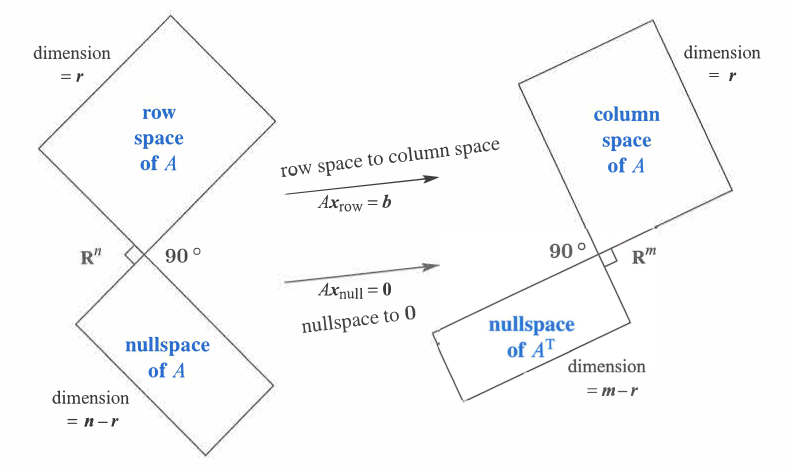

*Картинка из: [Gilbert Strang - Introduction to Linear Algebra (2016, Wellesley-Cambridge Press) ]*

Матрица - это четыре подпространства: 

(1) Пространство строк (столбцов матрицы $A^T$)  - $C(A^T)$

(2) Пространство столбцов матрицы $A$ - $C(A)$

(3) Нуль-пространство строк (столбцов матрицы $A^T$)   - $N(A^T)$

(4) Нуль- пространство столбцов матрицы (A) - $N(A)$

$N(A)\perp C(A^T)$ а $N(A^T)\perp C(A)$

Пространства (1) и (2) имеют одинаковую размерность (размерность  - число линейно независимых компонент). Размерности нуль-пространств не обязаны совпадать!  

Если у нас есть вектор $\vec{x}$ из пространства строк $C(A^T)$, то, когда мы на него действуем матрицей $A$, она переводит его в вектор пространства столбцов $C(A)$. Если же матрица  $A$ переводит вектор  $\vec{x}$ в нулевой вектор, то говорят, что $\vec{x}$ принадлежит нуль-пространству матрицы $A$ $N(A)$. Нуль-пространство матрицы $A$ дополняет пространство строк до полного пространства размерности n (число строк в матрице). Аналогичная ситуация с матрицей $A^T$, когда она действует на вектор $\vec{b}$ из пространства столбцов (2), то она переводит его в вектор пространства строк. , а если  $\vec{b}$ из нуль-пространства матрицы $A^T$, то она переводит его в нуль-вектор. Поэтому пространства 

 Для квадратной матрицы, у которой все столбцы (а, следовательно, и строки) линейно независимы, существует обратная матрица, которая однозначно переводит любой вектор пространства строк в соответствующий вектор пространства столбцов. Пространства (2) и (3) и (1) и (4) соотвественно попарно ортогональны (по сути это было сказано в двух предложения выше).

Обратная матрица:

clearvars
% квадратная матрица  - СЛАУ полностью определена
A = rand(10);
b = rand([10,1]);
x1 = inv(A)*b; %  x = (A^-1)*b, функция inv считает обратную матрицу
x2 = A\b; % это более быстрый вариант решения системы уравнений
norm(x1-x2)
% оба варианта дают одинаковый результат

Матрица квадратная (mxm), тут все однозначно, у квадратной матрицы есть обратная (если все ее столбцы линейно независимы). Обратная матрица - это такая матрица, которая для любого вектора из пространства $R^m$ возвращает подпрострнаства строк. 

clearvars
% квадратная матрица  - СЛАУ полностью определена
A = rand(10);
A(:,1) = A(:,2); % делаем матрицу сингулярной (матлаб решает задачу, но ругается) 
b = rand([10,1]);
x1 = inv(A)*b ;
x2 = A\b;
norm(x1-x2)

Но на практике число параметров оптимизации обычно не равно числу экспериментальных точек,

оно  существенно меньше, поэтому матрица должна быть прямоугольной а не квадратной 

clearvars
A = rand([100,5]);
b = rand([100,1]);
x1 = inv(A)*b
x2 = A\b

По ячейке выше возникает два вопроса:

1) Почему первое не сработало, а второе сработало, почему нельзя инвертировать прямоугольную матрицу $A^{n \times m }$?  

2) Почему сработало второе?

Ответ на первый вопрос дает картинка пространств прямоугольной матрицы выше. Тут, кажется, проблема в том, что такая матрица (обратная к прямоугольной) не будет универсально работать для любого вектора $\vec{b}$. Если вектор $\vec{b}$ принадлежит нуль-пространству матрицы $A^T$, то каков должен быть вектор $\vec{x}$, чтобы  матрицей $A$ мы перевели его в нуль-пространство матрицы $A^T$? Как мы могли вообще оказаться в этом нуль-пространстве? Если матрица $A$ действует на $\vec{x}$ из пространства строк - получаем вектор пространства столбцов, а если $\vec{x}$  из нуль-пространства матрицы $A$, получаем ноль-вектор.

А чтобы ответить на второй вопрос можно посмотреть на алгоритм функции **mldivide **или** \** :

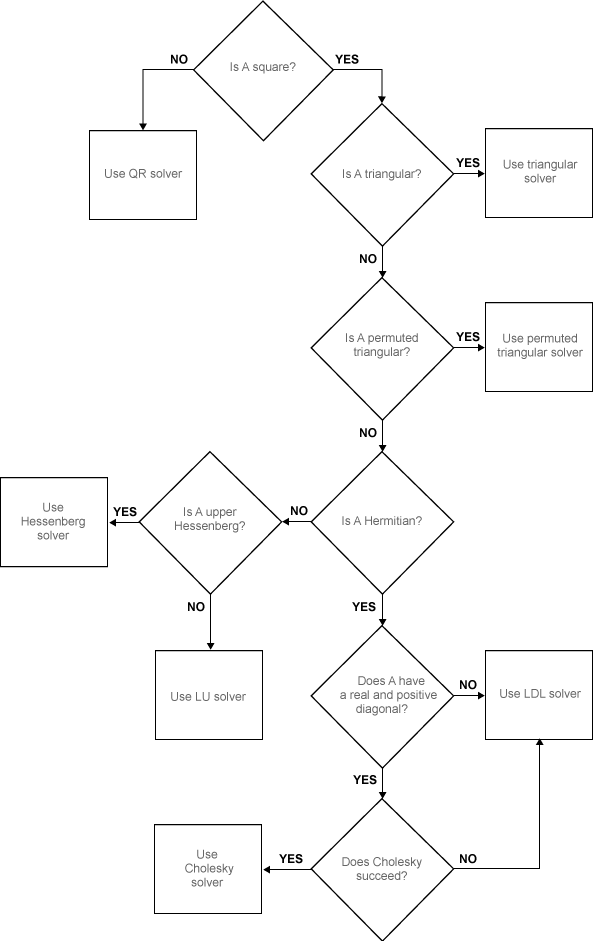

*Картинка алгоритма работы функции mldivide из help MATLAB*

Видно, что матлаб использует нескоторый таинственный QR солвер.  

Если представить вектор $\vec b$ в виде суммы составляющих в пространстсве столбцов и в нуль пространстве матрицы $A^T$ (которое дополняет пространство столбцов до пространства $R^m$)


$$A\vec{x}=\vec{b}=\vec{p} + \vec{e}$$


Картина с точки зрения линейной алгебры, если вектор $\vec{b}$ не лежит в пространстве столбцов матрицы $A$, то его можно разделить на две составляющие:

 -  нормальную пространству столбцов (то есть принадлежащая нульпространству $A^T$)

 - и лежащую в пространстве столбцов матрицы $A$

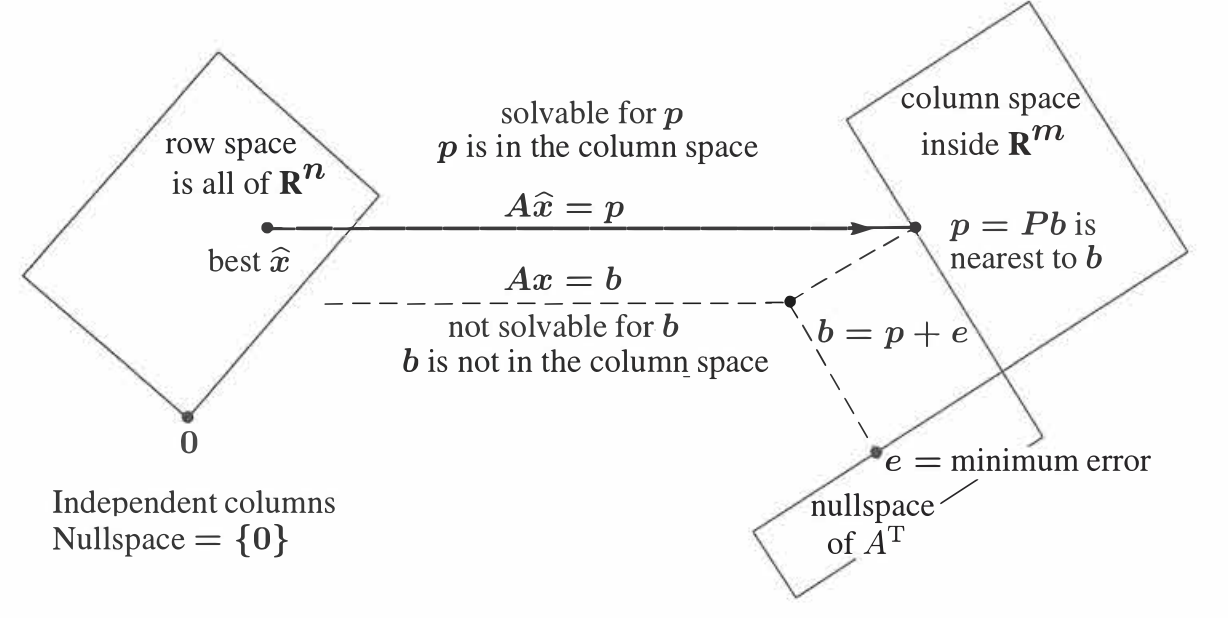

*[Gilbert Strang - Linear Algebra for Everyone (2020, Wellesley - Cambridge Press)]*

Идея в том, чтобы найти такой вектор $\vec{\hat x}$, который при действии на него матрицей $A
$ переходит в вектор $\vec{p}$ такой, что составляющая вектора $\vec{b}$, лежащая  в нуль-пространстве $A^T$минимальна, то есть $\vec{e}=\vec{b} - \vec{p}$ минимальна

В принципе, в качестве скалярной  меры "минимальности"  можно взять модуль вектора, можно сумму модулей его координат, можно максимальное значение координаты и т.д.

Мы далее будем минимизировать квадрат модуля ошибки (то есть, решать задачу метода наименьших квадратов), у подобного выбора есть статистическое обоснование в виде принципа максимального правдоподобия, который мы рассмотрим в следующий раз. 

Итак, минимизируемая функция (функция невязки в общих терминах задач оптимизации):


$$\Phi(\vec{x)= \vec{e}^T\vec{e}=||A\vec{x}-\vec{b}||^2 = (A\vec{x}-\vec{b})^T( A\vec{x}-\vec{b}) = \vec{x}^TA^TA\vec{x} -2(\vec{x}^TA^T)\vec{b}+\vec{b}^T\vec{b} $$


Видно, что функция невязки для задачи линейной оптимизации - квадратична относительно переменных отимизации, почему она названа линейной?!

Условие минимума модуля ошибки $\vec{e}$ - равенство нулю градиента  $\nabla_x(\vec{e}^T\vec{e})=0$, немного векторного анализа, и  это дает:


$$ \nabla_x(\vec{e}^T\vec{e})= 2[\nabla(\vec{x}^TA^T)]^TA\vec{x}   -2A^T\vec{b}=A^TA\vec{x} - A^T\vec{b}=0$$


||| Правило дифференцирования скалярного произведения:

||| $\nabla(\vec{a}^T\vec{b})= (\nabla\vec{a})^T\vec{b} + (\vec{a})^T(\nabla\vec{b}) $ => $\nabla(\vec{a}^T\vec{a})= 2(\nabla\vec{a})^T\vec{a} $

||| Правило дифференцирования матриц:

 |||$\nabla(A\vec{x})=A\nabla\vec{x}$, а $\nabla(\vec{x}^TA)=A^T\nabla\vec{x}$, $\nabla_x\vec{x} = I$

В итоге имеет уравнение:

$A^TA\vec{x} = A^T\vec{b}$                                                                        (1)

Отсюда, минимизатор :

$\vec{x}^* = (A^TA)^{-1}A^T\vec{b}$                                                                 (2)

$A^{\dagger} = (A^TA)^{-1}A^T$ - псевдо обратная матрица - оператор, который переводит произвольный вектор $\vec{b}$в вектор пространства строк матрицы $A$, если вектор $\vec{b}$ принадлежал пространству столбцов матрицы $A$; и в ноль, если $\vec{b}$принадлежал нуль-пространству матрицы $A^T$

#### Геометрический смысл псевдообратной матрицы:

Псевдообратная матрица, действуя на вектор $\vec{b}$, переводит его в вектор пространства строк $\vec{x}^*$, такой, что действие на этот вектор матрицы $A$ переводит его в проекцию вектора $\vec{b}$ на пространство столбцов матрицы $A$.

$A\vec{x}^* = A(A^TA)^{-1}A^T\vec{b}=P_A\vec{b}$                                                (3)

$P_A=A(A^TA)^{-1}A^T=AA^{\dagger}$ -  оператор проецирования произвольного вектора на векторное пространство столбцов матрицы $A$:


$$P_A \vec{b}=\vec{p}$$


% Проекция вектора на пространство столбцов матрицы из двух столбцов
 
clearvars
% генерим случаные вектора в трехмерном пространстве
a1 = (0.5 - rand(3,1)); 
a2 = (0.5 - rand(3,1));
R = [0.72, -50.7,161.3 ];% модуль-тетта-фи - сферическая система координат дял трехмерного вектора
r = R(1);thetta = R(2);phi = R(3);
b = [r*cosd(thetta)*sind(phi);r*cosd(thetta)*cosd(phi);r*sind(thetta)] ;% некоторый вектор
A = [a1,a2];
PA = A*inv(A'*A)*A'; % матрица проецирования
p = PA*b ;% составляющая вектора в пространстве столбцов
e = b - p;  % составляющая вектора перпендикулярная пространству столбцов
draw_vector([],'Проекция вектора на подпространство матрицы A',...
["a_1" "a_2" "b" "p||A" "e\perpA"],"vector",a1,a2, b,p,e);

**Как считать псевдообратную матрицу?**

Напрямую:

$A^{\dagger}=inv(A^TA)A^T$ - используется метод разложения Гаусса (LU - факторизация)

При помощи QR факторизации:

$A=QR$ ($R$ - квадратная матрица, $Q$ - ортогональная матрица)

QR-факторизация дает: $A^{\dagger}=(R^TQ^TQR)^{-1}R^TQ^T=(R^TR)^{-1}R^TQ^T=R^{-1}Q^T$

При помощи SVD разложения:

$A = U\Sigma V^T$  ($A$ - матрица размером nxm, $U,V$ - ортонормированные матрицы размером (nxn) и (mxm) соотвественно ($U^TU=I, V^TV=I$), $\Sigma$ - матрица сингулярных значений размером (nxm))

SVD - разложение дает: $A^{\dagger}=(A^TA)^{-1}A^T=(V\Sigma^T\Sigma V^T)^{-1}V\Sigma^T U=V(\Sigma^T\Sigma)^{-1}\Sigma^TU^T=V\Sigma^{\dagger}U^T$, $\Sigma^{\dagger} = \matrix{1/\sigma_1&\dots&0\cr 0 & \ddots &0 \cr0&\dots& 1/\sigma_r}$ 

В формуле выше, $r$ обозначает ранг матрицы$A$, если матрица имеет m линейно независимых столбцов, то $r=m$

SVD можно использовать и для матриц, у которых столбцы являются линейно зависимыми, то есть ранг матрицы $r<m$, тогда:


$$\Sigma^{\dagger} = \matrix{1/\sigma_1&0&&&\dots&0\cr 
0 & \ddots &&&\dots&0 \cr
0&\dots& 1/\sigma_r&0&\dots&0\cr 
0&\dots & \dots  &0&\dots& 0\cr
0&&&&\ddots\cr
0&\dots&\dots&&\dots&0}$$


То есть, матрица дополняется нулями до размера mxm

clearvars
A = rand(100,2);
b = rand(100,1);
[Q,R] = qr(A,"econ"); %econ значит, что возращается не полная матрица R и Q, а только размером с ранг данных
%[Q,R] = qr(A)
[u,S,v] = svd(A,"econ","vector");

Псевдообратная матрица $A^{\dagger}$:

ApseudoDir = inv(A'*A)*A' % напрямую (самый медленный способ)
ApseudoQR = R\Q' % через QR - факторизацию
ApseudoSVD = v*diag(1./S)*u' % через SVD - разложение
bmldivide = A\b % по сути тоже через QR факторизацию
normApseudoDir = norm( A*ApseudoDir*b - b) % модуль ошибки (составляющей ортогональной пространству столбцов матрицы A)
normApseudoQR = norm( A*ApseudoQR*b - b)
normApseudoSVD = norm( A*ApseudoSVD*b - b)
normmlDivide = norm(b - A*bmldivide)

А что если матрица имеет зависимые столбцы?

clearvars
a = rand(5);
e = 1e-32;
A = [a,2*a+e];
b = rand(5,1);
[Q,R] = qr(A,"econ");
[u,S,v] = svd(A,"econ","vector");
ApseudoDir = inv(A'*A)*A'; % напрямую (самый медленный способ)
ApseudoQR = R\Q'; % через QR - факторизацию
ApseudoSVD = v*diag(1./S)*u'; % через SVD - разложение
bmldivide = A\b; % по сути тоже через QR факторизацию
normApseudoDir = norm( A*ApseudoDir*b - b)
normApseudoQR = norm( A*ApseudoQR*b - b)
normApseudoSVD = norm( A*ApseudoSVD*b - b)
normmlDivide = norm(b - A*bmldivide)

#### Примеры линейной оптимизации когда столбцы матрицы $A$ линейно независимы

#### Полиномиальная аппркосимация и линейная оптимизация и линейная оптимизация линейно независимыми функциями произвольного базиса

Полиномиальный фиттинг  - частный случай линейной оптимизации, для базиса полиномиальных функций столбцы матрица $A$ линейно независимы (насоклько это возможно).

Пусть $\vec t = \matrix {t_1 \cr \vdots \cr t_N}$ - вектор независиммых переменных, полиномиальная функция имеет вид:


$$\vec y (\vec t)= a_1 \vec  {t}^0 +\vec{t}^1 + ... + \vec{t}^{P-1} =[\matrix {1 & \dots & t_1^{i-1} & \dots &t_1^{P-1} \cr  \vdots & & \vdots & & \vdots \cr 1 & \dots & t_j^{i-1}& \dots & t_j^{P-1} \cr   \vdots & & \vdots & & \vdots \cr t_j^{i-1}& \dots & t_j^{P-1} & \dots & t_{N}^{P-1} } ] [\matrix{a_1 \cr \vdots \cr a_i \cr \vdots \cr a_P}] = V\vec{a}$$


$V$ - матрица Вандермонда - матрица размером [NxP] (вместо $A$ ранее), $\vec{a}$ - вектор параметров линейной оптимизации (вместо $\vec {x}$ ранее).

Если число измеренных точек (N) больше числа коэффициентов полинома, то, данная переопределенная система имеет решение в форме псевдообратной матрицы $\vec{a}$.

В общем случае линейная оптимизация по некоторому базису может быть записана как:


$$\vec y (\vec t)= V\vec{a}=[\matrix {\vec \phi(\vec t,1) ,& \dots & \vec \phi(\vec t,i) ,& \dots & \vec \phi(\vec t,m) }]\vec{a}$$


$ \vec \phi(\vec t,i) $ - базисная функция, производит вектор-столбец из вектора независимых переменных $\vec t$ и номера столбца

Например для стандартного полиномиального базиса:


$$ \vec \phi_{standard}(\vec t,i) = \vec{t}^{i-1}$$


А, например, для тригонометрического базиса:


$$ \vec \phi_{trig}(\vec t,i) =\{ \matrix { cos(i\pi\vec{t}) &для& четных&i \cr sin(i\pi\vec{t}) &для&нечетных& i}$$


Модель экспериментальных данных

clearvars
% параметры экспериментальных данных
N=100; % число точек измерения
t = transpose(linspace(-1,1,N)); % независисмые переменные
type_experiment = "legP"; % тип реальнйо функции 
P = 3; % степень полинома
a1=1;
a2=1.992;
a3=0.256;
a4=0.0218;
a5=-0.55829;
e = 0; % амплитуда шумов 
a_real = [a1;a2;a3;a4;a5];
% заполняем массив "экспериментальных" данных
y = 0;
Pfun = producing_function(type_experiment,t);
for ii = 1:P
    y = y + a_real(ii)*Pfun(ii);
end
y = y + e*mean(y)*randn(size(y))/100;
ax = get_next_ax();
plot(ax,t,y,"ob");
title(ax,"Экспериментальные данные: "+ rus(type_experiment) + ", m=" + P)

Модель для фиттинга:

% параметры полинома которым фитим
type_fit = "legP"; % тип базиса для фитинга
Pfit = 3 ;% степень полинома для фитинга
V = vandermatrix(t,Pfit,type_fit); % формируем матрицу Вандермонда
tb = table();
tb.a_real = a_real(1:Pfit);
tb.a_fitted_qr = V\y; % решается методом qr факторизации

tb.a_fitted_pinv= pinv(V)*y;% решает путем SVD разложения матрицы
tb.a_lsqr = lsqminnorm(V,y) ; % минмизирует норму x (поэтому подходит для матриц А близких к сингулярным

a_polyfit = transpose(polyfit(t,y,Pfit-1)); % про polyfit дальше подробнее, но она решает задачу методом QR факторизации 
tb.a_polyfit = a_polyfit(end:-1:1);
tb
ax = get_named_ax("Сравнение различных способов решения задачи линейной оптимизации");
plot(ax,t,y,"o")
hold(ax,"on");
    plot(t,V*tb.a_fitted_qr,'+r')
    plot(t,V*tb.a_fitted_pinv,'g',"Marker","diamond")
    plot(t,V*tb.a_lsqr,'c')
    plot(t,polyval(a_polyfit,t),'m')
hold(ax,"off")
legend(ax,["y" "y = A*(A\\y)" "y = A*(pinv(A)*y)" "y=A*lsqrminnorm(A,y)" "Polyfit"],Location="bestoutside")

Сравнение скорости решения:

tm = table();
tm.t_fitted_qr = timeit(@()V\y,1); % решается методом qr факторизации
tm.t_fitted_pinv= timeit(@()pinv(V)*y,1); % решается через СВД разложение
tm.t_lsqr = timeit(@()lsqminnorm(V,y),1) ; % решается минимизацийе нормы стадартного отклонения итерационным способом
tm.t_polyfit = timeit(@()polyfit(t,y,Pfit-1),1);
tm

### Отличие полиномов Лежандра от стандартного базиса

Полиномы Лежандра - ортогональны (в терминах функционального анализа)


$$\int_{-1}^{+1}P_n(x)P_m(x)dx=\{ { \matrix{ 1 & для &m=n\cr 0&для&m\ne n }}$$
 

Первые несколько полиномов:  [Abramowitz and Stegun, "Handbook of Mathematical functions", Table 22.9.]

P0(x) = 1

P1(x) = x

P2(x) = 3/2*x.^2 - 1/2

P3(x) = 5/2*x.^3 - 3/2*x

P4(x) = 4.375*x.^4 - 3.75*x.^2 + 3/8

P5(x) = 7.875*x.^5 - 8.75*x.^3 + 1.875*x

clearvars
% Проверим ортогоняльность полиномов Лежандра
P0 = @(x) ones(size(x))*sqrt(1/2);
P1 = @(x) x*sqrt(3/2);
P2 = @(x) (3/2*x.^2 - 1/2)*sqrt(5/2);
P3 = @(x) (5/2*x.^3 - 3/2*x)*sqrt(7/2);
P4 = @(x) (3/8 - 3.75*x.^2 + 4.375*x.^4)*sqrt(9/2);
P5 = @(x) (1.875*x - 8.75*x.^3 + 7.875*x.^5)*sqrt(11/2);
% численное интегрирование:
integral(@(x) P1(x).*P4(x),-1,1)

Отличие различных полиномиальных базисов с точки зрения линейной алгебры можно посмотреть по тому насколько матрица Вандермонда каждого из базисов близка к сингулярной

Для этого у нас есть SVD - разложение

clearvars
N=100; % число точек измерения
t = transpose(linspace(-1,1,N)); % независисмые переменные
polynomial_degree = 20;
type1 = "stand" ; % тип реальнйо функции 
type2 = "legP" ;% тип реальнйо функции 
V_type1 = vandermatrix(t,polynomial_degree,type1); % формируем матрицу Вандермонда
V_type2 = vandermatrix(t,polynomial_degree,type2);

S_type1 = svds(V_type1,polynomial_degree); % хотим посмотреть SVD спектр матрицы Вандермонда
S_type2 = svds(V_type2,polynomial_degree);
N = 1:polynomial_degree;
ax = get_next_ax();
plot(ax,N,S_type1,"or",N,S_type2,"+b");legend(ax,[rus(type1), rus(type2)])
ylabel("Спектр сингулярных значений")
type1_rank = rank(V_type1)
type2_rank = rank(V_type2) % значит все колонки независимы!
plot(get_named_ax(rus(type1)),V_type1); ylabel(rus(type1))
plot(get_named_ax(rus(type2)),V_type2);ylabel(rus(type2))

В общем, основной вывод тут, что стандартный базис достаточно быстро становится сингулярным 

#### Оценка погрешности полиномиальной аппроксимации

Обычно полиномиальная аппроксимация может использоваться для следующих вещей:

1. Получить вектор параметров  (например, может быть нужна полка для линейной аппроксимации, скорость линейного роста чего-то от времени или ускорение). При этом важно знать не только сам вектор параметров, но и вариацию коэффициентов для каждой из координат этого вектора

2. Полиномиальная аппркосимация может быть использована для получения некоторой гладкой кривой, которая затем используется для получения значений в некоторых заданных точках. При этом важны не только сами значения в этих точках, но и погрешность. Это что-то вроде задачи интерполяции, но интерполяция - это точная кусочная аппросимация, поэтому из нее невозможно получить оценку погрешности. Для примера рисунок ниже - данные по температурной зависимости теплопроводности, поулчаемые с установки квазистационарного теплового режима:

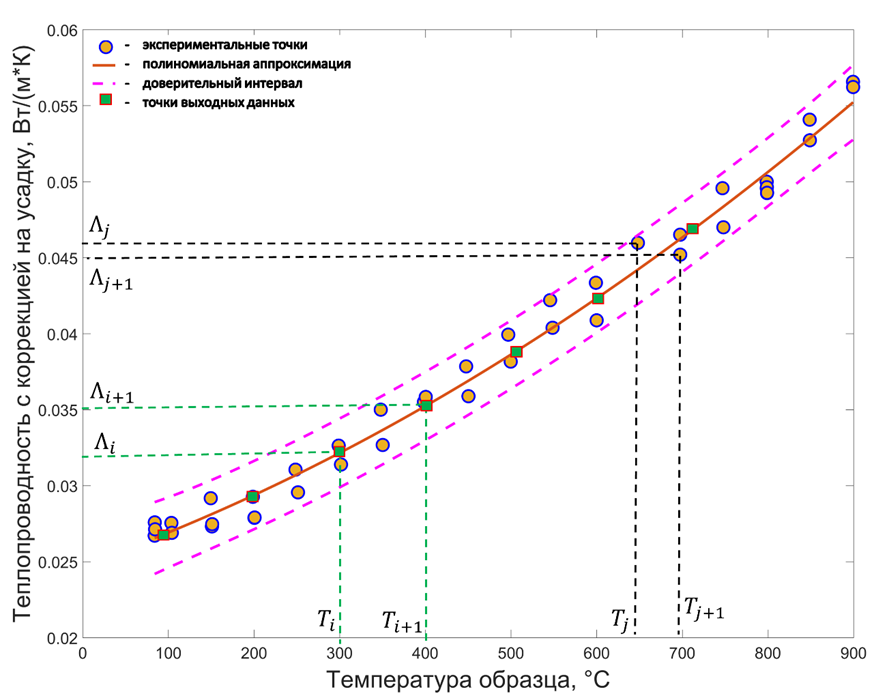

У нас есть некоторый разброс точек, которые в целом ложаться на одну кривую, но эти точки имеют нерегулярное расположение по обеим осям. Хочется получить результат на регулярное сетке, а также оценить погрешность этих данных. 

#### Математика для оценки погрешности.

Вектор невязки:


$$\vec{e} = \vec{b} - AA^{\dagger}\vec{b} = [I  - AA^{\dagger}]\vec{b}$$
 

( $[I-AA^{\dagger}]$ - оператор построения вектора, ортогонального векторному пространству столбцов матрицы $A$)

Качество аппроксимаци, тут применяется R- параметр:


$$R = 1-(\frac {||\vec{e}||}{||\vec{b} - <\vec{b}>||})^2$$


Напомню определение : 

$Var(\psi) = \mathbb{E}[((\psi - \mathbb{E}(\psi))^2]$ - вариация, 

$Cov(\psi,\phi)=\mathbb{E}[(\psi - \mathbb{E}(\psi))(\phi  - \mathbb{E}(\phi))]$ - ковариация двух случайных скалярных величин, $\mathbb{E}$ - математическое ожидание

Для векторной величины, матрица ковариации:

Диагональные элементы матрицы $C_{nn}$- коэффициенты вариации ($n=1{...}N$),  для  $n$ - го  свойства : $C_{nn}=\frac {\sum_{i=1}^{M}(x_{ni}-\mu_n)^2}{M-1}$  

Если из диагональных элементов извлечь корень и поделить на количество экспериментов $L$, то получим стандартное отклонение среднего арифметического.

Элементы матрицы $C$, стоящие вне диагонали, -  коэффициенты ковариации   $n$ - го  и $m$ - го свойств: $C_{nk}=\frac {\sum_{i=1}^{M}[ (x_{ni}-\mu_n)(x_{ki}-\mu_k)]} {M-1}$ ($n,k=1{...}N , n \not = k$) 

Матрица ковариации вектора параметров $\vec {a}$:


$$Cov(\vec{a}) = (A^TA)^{-1}\sigma$$



$$\sigma =||\vec{e}||^2 = \vec{e}^T\vec{e}/(n-m) = (\vec{b} - AA^{\dagger}\vec{b})^T(\vec{b} - AA^{\dagger}\vec{b})/(n-m)$$


(интересно, что  $\vec{e}^T\vec{e} = \vec{b}^T(I- AA^{\dagger})^T(I- AA^{\dagger})\vec{b}=\vec{b}^T[I- A^{\dagger^T}A^T - AA^{\dagger} + A^{\dagger^T}A^TAA^{\dagger} ]\vec{b}=\vec{b}^T[I-AA^{\dagger} ]\vec{b}=\vec{b}^T\vec{e}$ - скалярное произведение вектора $\vec{b}$на вектор $\vec{e}$, что логично, так как $\vec{b}=\vec{p} + \vec{e}$, но при этом $\vec{p}$ ортогонален вектору  $\vec{e}$)

$n $ - число точек, $m$ - число коэффициентов полинома, $n-m$ - число степеней свободы, это размерность нуль-пространства матрицы $A^T$ - пространства ошибки!

Если $A = QR$ - qr - разложение матрицы, то


$$Cov(\vec{a}) = (A^TA)^{-1}\sigma = (R^TQ^TQR)^{-1}\sigma =  (R^TR)^{-1}\sigma$$


$A_{interp}$ - новая матрица, построенная на другой сетке, для которой нам надо оценить доверительный интервал

$\vec{b}_{interp} = A_{interp}A^{\dagger}\vec{b}=A_{interp}\vec{a}$ ($\vec{a}$ - вектор коэффициентов полинома, который определен при решении задачи линейной оптимизации на сетке экспериментальных данных)

$Cov(\vec{b}_{interp})=A_{interp}Cov(\vec{a})A_{interp}^T$ - матрица ковариации рассчитанных через нашу аппроксимацию значений на нужной нам сетке координат (эта формула следует из общего правила расчета ковариации случаной величины, являющейся линейной комбинацией) 

Диагональные элементы этой матрицы - коэффициенты вариации (квадратичные отклонения для рассчитанных значений).


$$\vec{b}_{interp} \pm St\cdot \sqrt{diag[Cov(\vec{b}_{interp})]}$$


$St$ - коэффициент Стьюдента для числа испытаний N

Приведенные выше формулы являюстя универсальными, дальше рассмотрим их применение в матлаб на примере встроенной функции для полиномиальной аппроксимации polyfit - polyval

% пытаемся тоже самое посчитать вручную
A=rand(10,3);

diag(inv(A'*A))

[Q,R]=qr(A,0);
sum(inv(R).^2,2)

#### Полиномиальный фиттинг в матлаб:

% блок генерации исходных данных скопирован с того, что было раньше
clearvars
% параметры экспериментальных данных
N=100; % число точек измерения
t = transpose(linspace(-1,1,N)); % независисмые переменные
type_experiment = "legP"; % тип реальнйо функции 
P = 3; % степень полинома
a1=1;
a2=1.992;
a3=0.256;
a4=0.0218;
a5=-0.55829;
e = 12.91; % амплитуда шумов 
a_real = [a1;a2;a3;a4;a5];
% заполняем массив "экспериментальных" данных
y = 0;
Pfun = producing_function(type_experiment,t);
for ii = 1:P
    y = y + a_real(ii)*Pfun(ii);
end
y = y + e*mean(y)*randn(size(y))/100;
ax = get_next_ax();
plot(ax,t,y,"ob");
title(ax,"Экспериментальные данные: "+ rus(type_experiment) + ", m=" + P)

Для фитинга полиномами стандартного базиса используется функция polyfit

[p,STD]= polyfit(t,y,P) - функция для решения задачи фитинга полиномами стандартного базиса

Входные ургументы:

        x,y - экспериментальные точки

        P - степень полинома (начиная с нуля)

Выходные аргументы:

    p - вектор коэффициентов в порядке убывания степени полинома (не так как в самодельно версии)

    STD - структура, которая хранит в себе данные а качестве аппроксимации и данные для расчета погрешности             аппроксимации)

[y_int,delta_y]= polyval(x,p,STD) - функция для решения задачи фитинга полиномами стандартного базиса

входные аргументы 

    x - точки, в которых нужна интерполяция 

    p - коэффициенты полинома

    STD - структура, возвращаемая polyfit (см. предыдущие обозначения)

выходные аргументы

    y_int - рещультаты расчета полинома в точках x

    delta_y - стандартное отклонение от среденего (чтобы учесть вероятность надо домножить на коэффцииент стьюдента)

Также есть вариант, который сразу расчитывает доверительный интервал под заданную вероятность 

[yfitExtended,deltaExtended] = polyconf(pp,t,STD,'alpha',0.05); % позволяет сразу посчитать доверительный интервал, среди входных аргуметов alpha - 1 - p, где p - доверительная вероятность. 

[pp,STD] = polyfit(t,y,P) % функция для фиттинга стандартным базисом полиномов
V = vandermatrix(t,P+1,"stand") % считаем Вандерматрицу по самодельному способу
[Q,R] = qr(V,0) % делаем ее qr факторизацию
STD_R = STD.R % содержит матрицу R для расчета матрицы ковариации
[y_fit,delta] = polyval(pp,t,STD) % если в качестве дополнительного аргумента передать в функцию polyval структуру STD, то она вернет коэффициенты вариации дял каждой точки
[yfitExtended,deltaExtended] = polyconf(pp,t,STD,'alpha',0.05); % позволяет сразу посчитать доверительный интервал
ax = get_next_ax();
plot(ax,t,y,'bo')
hold(ax, "on")
plot(ax,t,y_fit,'r-')
plot(ax,t,y_fit+2*delta,'m--',t,y_fit-2*delta,'m--')

plot(ax,t,yfitExtended,'+y')
plot(ax,t,yfitExtended+deltaExtended,'g+',t,y_fit-deltaExtended,'g+')
title('Фиттинг данных полиномом')
legend('Data','Полиномиальный фиттинг','95% доверительный интервал')
hold(ax, "off")
mean(deltaExtended./delta)

polytool(t,y) % встроенная графиечская обертка для полиномиального фитинга

### Выводы по семинару 7

- Задача оптимизации - найти параметры, при которых модель минимизирует расхождения между ее предсказаниями и результатами измерений. Модель зависит как от переменных оптимизации, так и от независимых переменных (предикторов)

- Линейная оптимизация (регрессия) - случай, когда модель зависит от параметров линейно, то есть ее можно представит в виде $A\vec{a}$, где $\vec{a}$ - вектор параметров, а $A$ - матрица, зависящая только от независимых переменных.

- Примеры линейной оптимизации: полиномиальный фитинг, матрица $A$ - матрица Вандермонда, которая, например, для стандартного базиса имеет вид: $V = [\vec{t}^0,...,\vec{t}^i,....,\vec{t}^P]$, где $\vec{t}$ - вектор независимых переменных (верхний индекс - возведение в степень каждого элемента вектора).

- Если минимизируется квадрат модуля отклонения модели от наблюдаемых данных, то это задача наименьших квадратов

- С точки зрения линейной алгебры, задача наименьших квадратов состоит в том, чтобы найти такой линейный оператор $A^{\dagger}$, который при его действии на некоторый произвольный вектор $\vec{b}$ переводит его в пространство строк матрицы $A$, если  вектор $\vec{b}$ принадлежит пространству столбцов матрицы $A$ и в нулевой вектор, если он принадлежит пространству ортогональному пространству столбцов матрицы $A$ (нуль-пространство столбцов матрицы $A^T$).

- Таким образом, оператор  $AA^{\dagger}$ является оператором проецирования произвольного вектора на векторное пространство столбцов матрицы,  при его действии  вектор $\vec{b}$ он переводит его в вектор $\vec{p}$, принадлежащий пространству столбцов матрицы $A$, а вектор $\vec{e} = \vec{b} - \vec{p}$ - является ошибкой аппроксимации.

- Для полиномиальной аппроксимации, при увеличении степени полинома матрица $V$ становится близкой к сингулярной (что видно из спектра ее сингулярных значений), если требуется большой порядок полинома, ортогональные полиномы Лежандра являются предпочтительными

- Для полиномиально аппроксимации стандартным базисом можно пользоваться функцией 

[pp,STD] = polyfit(t,b,P-1) - a - вектор коэффициентов полинома, t - координаты, b  - вектор данных для фитинга, P - количество полиномиальных коэффициентов, STD- структура, хранящая данные нужные для оценки погрешности, a - вектор коэффициентов полинома в порядке убывания степени

[y,delta] = polyval(pp,t_new,STD)  - функция для расчета полинома, y - результат расчета, delta - ошибка аппроксимации ( *y* ± delta это примерно 68%-ный доверительный интервал,  *y* ± 2delta) -   95% ный.)

[y,delta] = polyval(pp,t_new,STD,'alpha',ALPHA)  - функция для расчета полинома, y - результат расчета, delta - ошибка аппроксимации для заданной доверительной вероятности, ALPHA = 0.05 соотвествует доверительной вероятности 95%.

### Семинар 8. Линейная регрессия (продолжение)

#### Несколько примеров линейной регрессии

#### Фиттинг поверхности в пространстве

Пример линейной регрессии - полиномиальный фитинг двумерных данных

Задача следующая, имеются данные $\vec{Y},\vec{X_1},\vec{X_2}$  - вектор-столбцы наблюдений некоторых параметров

В первом варианте предполагается, что $\vec{Y}$ зависит от $\vec{X_1}$  и $\vec{X_2}$  линейно, то есть каждую координату вектора$\vec{Y}$  можно выразить в виде линейной комбинации соотвествующих координат векторов $\vec{X_1}$  и $\vec{X_2}$  :

$Y_i=\beta_1 + \beta_2X_{1i} + \beta_3X_{2i} $ (i - индекс строки)


$$\vec{Y} = [\vec{1},\vec{X_1},\vec{X_2}][\matrix{\beta_1 \cr \beta_2 \cr \beta_3}]$$


Во втором варианте предполагается, что зависимость квадратичная:


$$Y_i=w_1 + w_2X_{1i} + w_3X_{2i} + w_4X_{1i}^2 + w_5X_{2i}^2 $$
 


$$\vec{Y} = [\vec{1},\vec{X_1},\vec{X_2},\vec{X_1}^{2},\vec{X_2}^2][\matrix{w_1 \cr w_2 \cr w_3 \cr w_4 \cr w_5}]$$


% данные из "https://raw.githubusercontent.com/probml/probml-data/main/data/moteData/moteData.mat"
% пример из книжки K.P.Murphy "Probabilistic machine learning. An introduction"
data = load(fullfile(get_folder(),"DataSurfFit.mat"))
Y = data.y;
X1 = data.X(:,1);
X2 = data.X(:,2);
N = numel(X1);
scatter3(X1,X2,Y)

Решаем задачу линейно регрессии для двух вариантов зависимости 

I1 = ones([N 1]);
V1 = [I1,data.X];% матрица полинома первой степени (три колонки)
W1 = lsqminnorm(V1,Y) % аппроксимируем линейной зависимостью
norm1 = norm(Y - V1*W1)
% W1 = V1\Y ;
V2 = [I1,data.X,data.X.^2]; % матрица для полинома второй степени (пять колонок)
W2 = lsqminnorm(V2,Y) % аппроксимируем квадратичной зависимостью
norm2 = norm(Y - V2*W2)
% W2 = V2\Y ; % аппроксимируем квадратичной зависимостью
% Функция lsqminnorm решает задачу Ax=b  в смысле наименьших квадратов
% Отличие функции x = lsqminnorm(A,b) от x = A\b в том, что она минимизирует не
% только норму квадратичного отклонения, но и (это актуально если матрица A является
% сингулярной) норму самого вектора 

% теперь построим поверхность по результатам интерполяции
M = 10

xrange = linspace(min(X1), max(X1), M);
yrange = linspace(min(X1), max(X2), M);
% оборачиваем расчет полинома в указатель на функцию (функция будет
% вызываться скалярно в цикле)
z_fun_linear =@(x,y,w) w(1)+ x*w(2) + y*w(3);
z_fun_square = @(x,y,w) z_fun_linear(x,y,w) +w(4)*x^2 + w(5)*y^2;
[Xgrid,Ygrid] = meshgrid(xrange,yrange);
Z1 = zeros(M);
Z2 = zeros(M);
for ii = 1:M
    for jj = 1:M
        x = Xgrid(ii,jj);y = Ygrid(ii,jj);
        Z1(ii,jj) = z_fun_linear(x,y,W1);
        Z2(ii,jj) = z_fun_square(x,y,W2);
    end
end
ax = get_next_ax();
surf(ax,Xgrid,Ygrid,Z1)
hold(ax,"on")
scatter3(ax,X1,X2,Y,"or")
hold(ax,"off")

ax = get_next_ax();
surf(Xgrid,Ygrid,Z2)
hold(ax,"on")
scatter3(ax,X1,X2,Y,"or")
hold(ax,"off")

% Двойной вложенный цикл это постыдно, упражнение: 
% сгенерить данные для поверхности без использования циклов

#### Пример 2. Линейная регрессия нелинейной задачи.

Иногда нелинейную задачу можно свести к линейной путем некоторого нелинейного пребразования, для примера рассмотрим следующую задачу:

Есть данные $\vec{y}$ и $\vec{x}$, предполагается, что $y(x)= \alpha_1 x^{\alpha_2 }\exp(-\frac{\alpha_3}{x})$, нужно найти параметры $\alpha_1, \alpha_2, \alpha_3$

Данная задача сводится к задаче линейной регрессии (несмотря на то, что в изначальной постановке параметры входят нелинейно, если прологарифмировать обе части, то:


$$ln(y)= ln(\alpha_1) +  \alpha_2*ln(x) - \alpha_3\frac{1}{x}$$


Если ввести новые переменные, то получи мзадачу линейной регрессии :

$\vec{Y} = ln(\vec{y})$  $\vec{X_1}=\ln(\vec{x})$  и $\vec{X_2} = 1/\vec{x}$ 

$\beta_1 = \ln(\alpha_1)$, $\beta_2 = \alpha_2$, $\beta_3 = -\alpha_3$


$$\vec{Y} = [\vec{1},\vec{X_1},\vec{X_2}][\matrix{\beta_1 \cr \beta_2 \cr \beta_3}]$$


clearvars
e = 0.2;
N = 62;
x = linspace(0.3,6,N)';
a = [20 -2 2.2];
y = a(1)*(x.^a(2)).*exp(-a(3)./x) + e*randn(N,1);
X1 = log(x);
X2 = 1./x;
I = ones([N,1]);
X = [I,X1,X2];
Y = log(y);
b = lsqminnorm(X,Y);
a_fitted = [exp(b(1)) b(2) -b(3)]
a_real=a
ax= get_next_ax();
scatter(ax,x,y);hold(ax,"on")
plot(ax,x,exp(X*b));hold(ax,"off");legend(ax,["Initial" "Fit"])

Вопрос что при всех этих нелинейных преобразованиях происходит с ошибкой....

### Погрешность линейной регрессии

**Введение. Понятия из статистики. Описательная статистика**

У нас есть случаная переменная, которая может принимать некоторый (дискретный) набор возможных значений:


$$\nu \sim \nu_1 \dots \nu_N$$
 

Вероятность переменной иметь некоторое определенноей значение из этого дискретного набора характеризуется набором вероятностей:

$P \sim p_1 \dots p_N$, $\Sigma_ip_i=1$

Для некоторой случайной переменной, которая берется из некоторого распределения $P$, математическое ожидание будет:

$\hat\nu=\mathbb{E}[\nu\sim P]=\Sigma_ip_i\nu_i$  - i - индексы возможных исходов! (их всего N штук)

Среднее значение результатов набора из $M$ испытаний:

$\mu_{\nu}=\frac{\Sigma_{j=1}^M\nu_j} {M}$ - применяется для экспериментальной оценки мат. ожидания по M испытаниям 

(j - перебирает испытания, испытаний было M штук)

Разброс некоторой переменной характеризуется вариацией:

$\mathbb{V}[\nu]=\mathbb{E}[(\nu-\hat\nu)^2]=\Sigma_ip_i(\nu_i-\hat\nu)^2=\mathbb{E}[(\nu^2]-(\mathbb{E}[\nu])^2$, 

Для экспериментальной оценки вариации по  выборке из $M$ испытаний:


$$S_{\nu\nu}= \frac {\Sigma_{j=1}^M(\nu_j-\hat\nu)^2} {M-1}$$


$std(x) = \sqrt{S_{\nu\nu}}$ - cтандартное отклонение 

Ковариация двух случаных переменных:

$Cov(\nu,\eta)=\mathbb{E}[(\nu-\mathbb{E}[\nu])(\eta - \mathbb{E}[\eta])]=\Sigma_{ij}p_{ij}(\nu_i-n)(\eta_i - m)$, 

$Cov(\nu,\nu)=\mathbb{V}(\nu)$,

clearvars
M = 100;% число испытаний
N = 9; % число цифр (число возможных исходов)
possible_values = transpose(1:1:N);% сами цифры все возможные значения
a = randi(N,M,1); % случайно выбирает значения в диапазоне от 1 до N, M раз
histogram(get_next_ax(),a,[1.5;possible_values(2:end) + diff(possible_values)/2])
tb = table();
tb.Average = mean(a); % считаем среднее значение (оценка математического ожидания)
p_i = 1/N; % вероятность выбрать конкретную цифру 
p = p_i*ones(N,1);% вектор вероятностей для всех цифр
tb.Expectation = p'*possible_values;
tb.STD2 = std(a)^2;
tb.Variation = p'*((possible_values-tb.Expectation).^2);
tb

Коэффициент корреляции двух случайных величин:


$$Cor(\eta,\nu)=\frac{Cov(\eta,\nu)}{\sqrt{\mathbb{V}(\eta)}\sqrt{\mathbb{V}(\nu)}}$$


Если у нас есть вектор-столбец измерений некоторой случайной величины x, то есть, каждая из координат этого вектора - образцы (сэмплы, розыгрыши) случайной величины x, экспериментальной оценкой вариации будет:

$S_{xx}=(\vec{X} - \mu_x\vec{I})^T(\vec{X}-\mu_x\vec{I})/(N-1)$, $\vec{I}$ - вектор состоящий из единиц,

$\mu_x=\frac{\sum_{i=1}^N(x_i)}{N}=\frac {\vec{I}\vec{X}^T}{N}$ - экспериментальная оценка математического ожидания.

Ковариации линейно комбинации двух случайных величин:


$$Cov(a\nu + b\eta)=a^2Cov(\nu,\nu) + 2abCov(\nu, \eta) + b^2Cov(\eta,\eta)=a^2\mathbb{V}(\nu) + 2abCov(\nu,\eta) + b^2\mathbb{V}(\eta)$$


Если у нас есть вектор случайных величин (то есть, вектор, координаты которого случайные величины, каждая получена из своего распределения, каждая имеет свое среднее и свою вариацию :


$$\vec{\beta}=[\matrix {\beta_1, & \dots & \beta_i, & \dots & \beta_N}]^T$$
 

Среднее значение этого вектора - тоже вектор, каждая из координат которого  - это среднее значение соотвествующей случайной величины:


$$\mathbb{E}[\vec{\beta}]=[\mathbb{E}[\beta_1],...,\mathbb{E}[\beta_i],...,\mathbb{E}[\beta_N]]$$


То можно ввести матрицу ковариации размером NxN) этого вектора, элемент i-й строки j-го столбца которой: 


$$K_{\beta ij}=Cov(\vec \beta)_{ij}=Cov(\beta_i,\beta_j)$$


На диагонали матрицы ковариации стоят, соответственно вариации.

Таким образом, матрица ковариации вектора случаных величин :


$$K_{\beta}=\mathbb{E}[(\vec\beta  - \mathbb{E}[\vec{\beta}])(\vec{\beta} - \mathbb{E}[\vec{\beta}])^T]$$


%вспомним что такое внешнее произведение:
clearvars
a = sym("a",[2,1],"real")
a*a'

Экспериментальная оценка матрицы ковариации:

Если у нас есть матрица измерений размером$N\times M$:

 $X=[\vec{X_1}^T, \dots ,\vec{X_i}^T,...,\vec{X_N}^T]^T$, в которой каждый столбец - это вектор сэмплов N случайных величин

Каждая $i$ - я строка матрицы $X$- это $M$ сэмплов случайной величины $x_i$ - компоненты случайного вектора $\vec{x}$

Для экспериментальной оценки матрицы ковариации:


$$K_X=[X-\vec{\mu}\vec{I_M}^T][X-\vec{\mu}\vec{I_M}^T]^T/(M-1)$$


$\vec{\mu}$ - вектор-столбец размером Nx1 средних значений каждой из строк


$$\vec{\mu}=\frac{X\vec{I_M}}{M}$$


clearvars
M = 3;
N=2;
a = sym("a",[1 M],"real"); % вектор сэмплов случайно величины a
b = sym("b",[1 M],"real");% вектор сэмплов случайной величины b
X = [a;b] % матрица измерений
Im = sym(ones(M,1))
mu = X*Im/M
mus = sym("mu",[N 1])
Mu = mus*Im'
Kx = (X-Mu)*(X-Mu)'
disp("Вариация случайной переменной x :")
disp(Kx(1,1));
Kx(1,2)

clearvars
x1 = randn([1 100]);
x2 = 1*x1 + randn([1 100]);
mu = [mean(x1);mean(x2)];
X = [x1-mu(1);x2-mu(2)];
X*X'/(99)
cov(X')

#### Распределения

Теперь плотность вероятности - не дискретная величина, а непрерывная, которая дается функцией 


$$p(x;\mu,\sigma,...)$$


$x - $переменная, а то, что стоит после запятой - параметры распределения,

Иногда бывает условное распределение вероятности (сегодня в явном виде не будет), то есть, например, распределение вероятности $x$, при заданном $y$ (тоже случайном, но фиксированном), записывают:

 
$$p(x|y;\mu,\sigma,...)$$


Кумулятивная вероятность - вероятность случайной переменной иметь значением меньше x


$$P(x|t<x)=\int_{-\infty}^{x} p(t)dt$$
 

Понятно, что $\int_{-\infty}^{+\infty} p(t)dt = 1$ 

Основные элементы описательной статистики:

 $\mathbb{E}[x]=\int_{-\infty}^{+\infty}xp(x)dx$ (еще это называют первым моментом)


$$\mathbb{V}[x]=\int_{-\infty}^{+\infty}(x-\mathbb{E}[x])^2p(x)dx=\int_{-\infty}^{+\infty}x^2p(x)dx-(\mathbb{E}[x])^2$$


Значок $x\sim P(x)$ обозначает, что случайная переменная $x$ берется из распределения $P(x)$. То есть это аналог вызова генератора случаных чисел, например, запись *x=rand() * в матлаб эквивалентна $x\sim P(x)$, где $ P(x)$ - равномерное распределение от -1 до 1.

Запись:


$$\zeta \sim \mathcal{N}(\mu,\sigma^2)$$


Обозначает что случайная переменная $\zeta$ получена из нормального распределения с параметрами $\mu$ и $\sigma$.

Формула для нормального распределения:


$$p(x;\mu,\sigma)= \frac {1}{\sqrt{2\pi\sigma^2}} e^{\frac {(x-\mu)^2}{2\sigma^2}}$$


clearvars
% строим нормальное распределение
mu=0; % первый параметр распределения
sig = 5.76; % второй параметр распределения
x = linspace(-10,10,100)';
distr_fun = norm_distribution_function(mu,sig);
plot(get_next_ax(),x,distr_fun(x))

Вероятность того, что переменная имеет значение меньше заданного (кумулятивнное распределение вероятности):


$$P(x|t<x)=\int_{-\infty}^{x} p(t)dt=\int_{-\infty}^{x} \frac {1}{\sqrt{2\pi\sigma^2}} e^{\frac {(t-\mu)^2}{2\sigma^2}}dt$$


Вероятность того, что случайная переменная распределенная нормально лежит в интервале от $x_1$ до $x_2$:


$$P(x\in[x_1,x_2])=P(x_2) - P(x_1)=\int_{x_1}^{x_2} \frac {1}{\sqrt{2\pi\sigma^2}} e^{\frac {(x-\mu)^2}{2\sigma^2}}dx=[\int_{-\infty}^{x_2}  - \int_{-\infty}^{x_1}]  \mathcal{N}(x;\mu,\sigma)dx$$


Код ниже рассчитывает вероятность того, что случайная величина $x $ распределенная нормально лежит в интервале $-m\sigma\leq x \leq m\sigma$

clearvars
x = linspace(-10,10,100)';
sig = 3.18;
distr_fun = norm_distribution_function(0,sig);
sigma_multiplier=1;
P = integral(distr_fun,-sigma_multiplier*sig,sigma_multiplier*sig);
% integral - функция численного интегрирования 
ax = get_next_ax();
area(ax,x,distr_fun(x),"FaceAlpha",0.2)
hold(ax,"on");
sub_x = x((x>=-sigma_multiplier*sig)&(x<=sigma_multiplier*sig));
area(sub_x,distr_fun(sub_x),"FaceAlpha",0.2);
title(ax,"P(-"+string(sigma_multiplier) + "*\sigma"+ "\leq x\leq "+string(sigma_multiplier) + "*\sigma)="+ string(P))
ylabel(ax," N(\mu,\sigma)")
xlabel(ax,"Значение x")
hold(ax,"off");

$erf(x)=\frac{2}{\sqrt{\pi}} \int_0 ^{x}e^{-t^2}dt$ - интеграл от гауссиана - специальная функция


$$P(x|t<x) = \frac{1}{2}[1-erf(-\frac{x}{\sqrt{2}})]$$


% это соотвенственнно точное значение
tb = table(P,erf(sigma_multiplier/sqrt(2)));
tb.Properties.VariableNames = ["Численное интегрирование" "Точное значение"];
tb

clearvars
% строим нормальное распределение
sig = 1;
mu = 0;
distr_fun = norm_distribution_function(mu,sig);
sigma_multiplier = 0.5:0.5:3;
P = zeros(numel(sigma_multiplier),1);
tic
%parfor ii = 1:numel(sigma_multiplier)
for ii = 1:numel(sigma_multiplier)
    m = sigma_multiplier(ii);
    % интегрируем численно от mu-m*sig до mu + m*sig
    P(ii) = integral(distr_fun,mu-m*sig,mu+m*sig); 
end
toc
ax = get_next_ax();

plot(ax,sigma_multiplier,P,"or-");
xlabel(ax,"Множитель дисперсии");
ylabel(ax,"Вероятность попасть в интервал")
table(sigma_multiplier(:),P,VariableNames = ["Множитель","Вероятность"])

$ \mathcal{N}(0,1)$ - стандартное нормальное распределение (функция randn)

Чтобы получить переменную, взятую из $\zeta \sim \mathcal{N}(\mu,\sigma^2)$ из переменной, взятой из стандартного распределения $ \eta \sim \mathcal{N}(0,1)$


$$\zeta \sim \mathcal{N}(\mu,\sigma^2) = \mu + \sigma^2 \mathcal{N}(0,1)$$


Важное распределение - хи квадрат. Хи-квадрат распределение показывает распределение значений суммы квадратов нормальных случаных переменных:


$$\chi^2_k=\sum_{i=1}^{k} Z_i^2$$


где $Z_i \sim \mathcal{N}(0,1)$

Важное распределение  - распределение Вейбулла (прочность хрупких материалов подчиняется статистике Вейбулла)

$p_{weib}(x|;a,b)=\frac{b}{a}(\frac{x}{a})^{b-a}e^{(-x/a)^b}$ для $x\ge0$

%в statistics and machine learning toolbox есть функция fitdist,
% которая позволяет подбирать распределение под данные 
data =  load(fullfile(get_folder(),"DataWeibDistr.mat"));
X = data.MAT;
scatter(get_next_ax(),1:numel(X),X)
fitdist(X,"Weibull")
% distributionFitter - приложения для фитинга распрелений

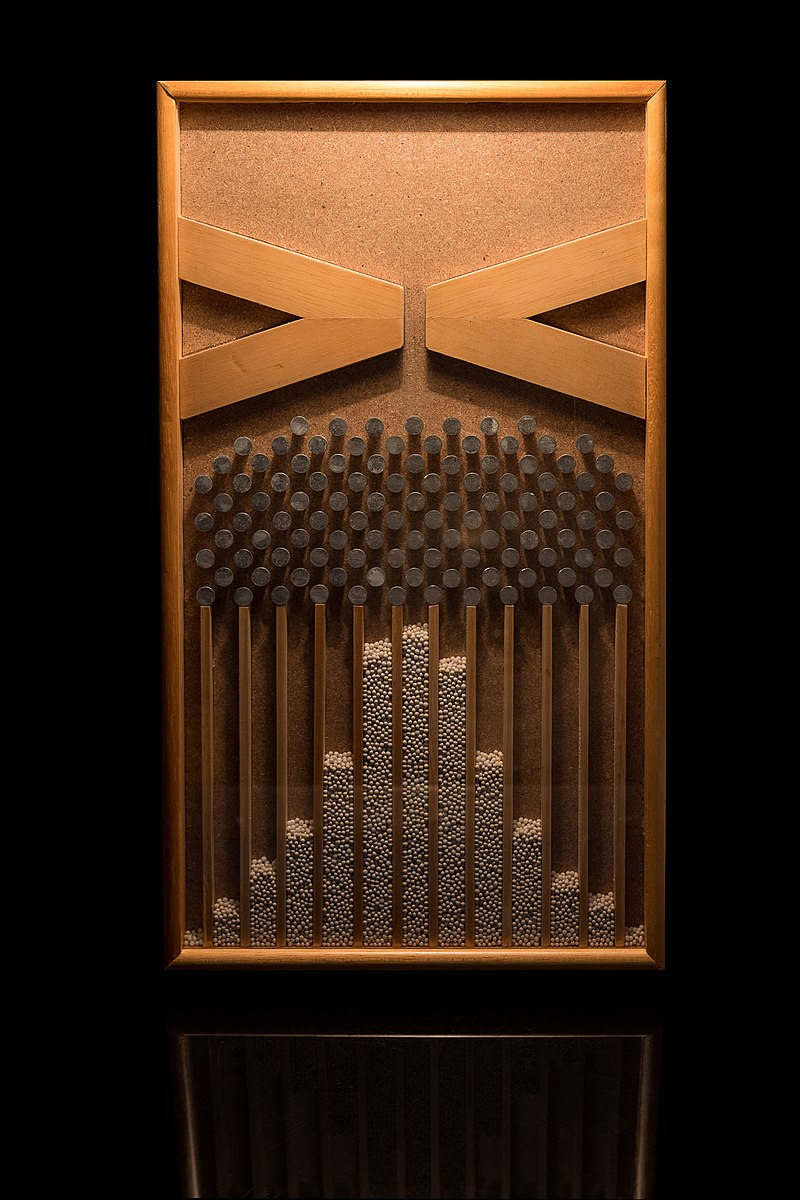

clearvars
% картинки разных распределений
% наша задача  - построить распределения на основе "экспериментальных" данных

M = 50; % число точек сетки
tmin=-5;tmax=286;t = transpose(linspace(tmin,tmax,M));
distrib = 'Normal'; % выбираем тип генератора случаных чисел 
mu=122.37; % первый параметр распределения
sigma = 6.98; % второй параметр распределения
N = 1e4; % число экспериментов
pd = make_dist(distrib,mu=mu,sig=sigma); %генерит генератор случайных чисел 
% для различных двухпараметрических распределений(обертка для встроенных генераторов, для всех кроме 
% нормального и равномерного распределения нужен statistical toolbox 
g = pd(N);% возращает вектор из N чисел, распределенных в соотвествии с данным распределением
distr = zeros(M-1,1);
for ii = 1:M-1
    distr(ii) = sum((g<t(ii+1))&(g>=t(ii)))/N; % считаем число точек, которые попали в интервал
end
sum_distr = sum(distr)
average_g = mean(g) % оценка среднего из среднего арифметического
var_g = (g - average_g)'*(g - average_g)/(N-1) % оценка вариации
ax= get_next_ax();
histogram(ax,g,t)
title(ax,distrib)
tb = table();
tb.mu = mu;tb.mean = average_g;tb.sig = sigma^2;tb.std = sqrt(var_g);
tb

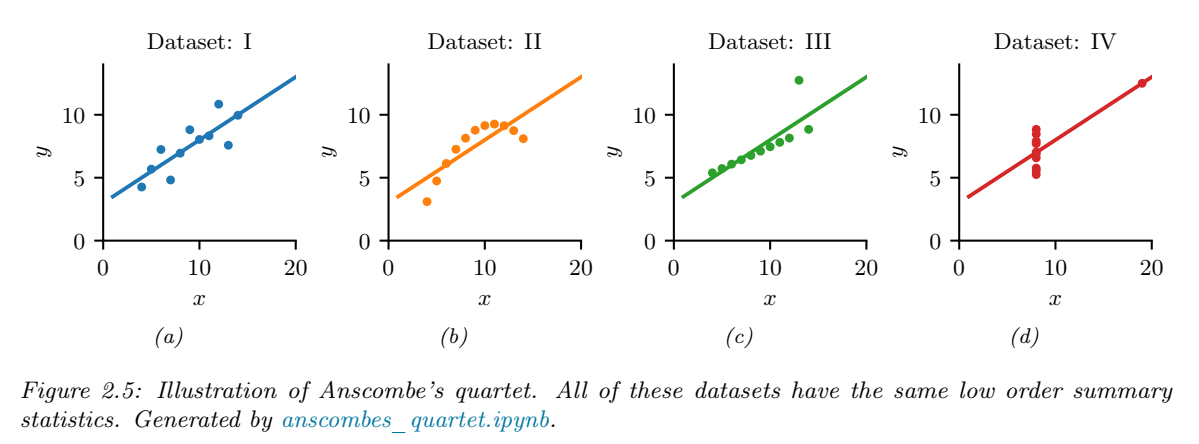

(картинка из книжки K.P.Murphy "Probabilistic machine learning. An introduction", иллюстрирующая недостаточность дескриптивной статистики, все эти наборы данных имеют одно среднее по каждому из столбцов, вариацию и коэффициент корреляции между x и y)

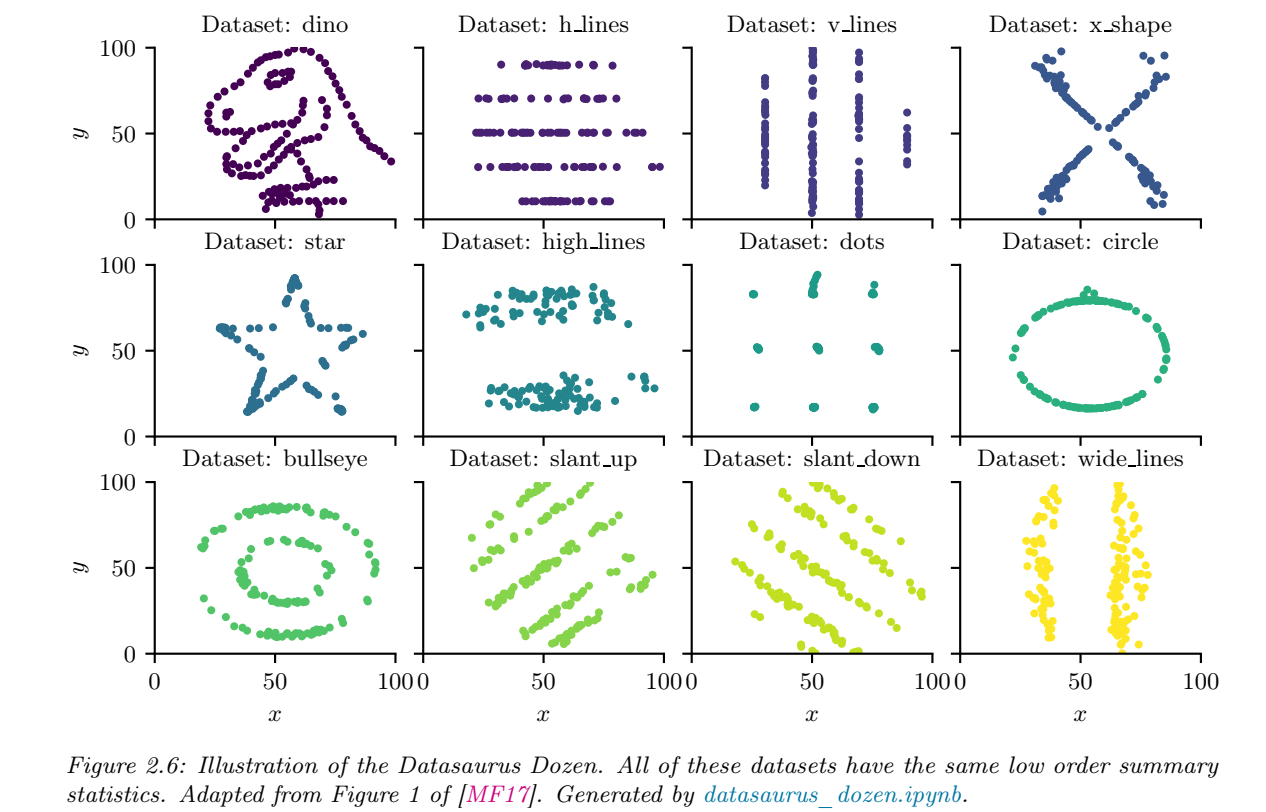

### Выводы по семинару 8

- Рассмотрены два примера линейной регрессии, первый - фиттинг данных поверхностью параболоида, второй  - сведение нелинейной функции к линейной путем нелинейного преобразования 

- Основные характеристики случайной велчины $\psi$ математическое ожидание $\mathbb{E}[\psi]$и вариация $\mathbb{V}[\psi]=\mathbb{E}[(\psi-\mathbb{E}[\psi])^2]$, для их оценки по выборке применяется среднее арифметическое и среднее квадратическое отклонение среднего

-  В качестве меры совместного изменеия двух случаных величин применяется ковариация $Cov(\nu,\eta)=\mathbb{E}[(\nu-\mathbb{E}[\nu])(\eta-\mathbb{E}[\eta])]$

- Для вектора случайных величин вводят матрицу вариации - ковариации, в которой каждый элементы i-й строки j-го столбца соотвествует ковариации его i-й и j-й координаты 

-  Если имеются измерения $X=[\vec{X_1}^T, \dots ,\vec{X_i}^T,...,\vec{X_N}^T]^T$, в которой каждый столбец - это вектор сэмплов N случайных величин. Каждая $i$ - я строка матрицы $X$- это $M$ сэмплов случайной величины $x_i$ - компоненты случайного вектора $\vec{x}$.  Для экспериментальной оценки матрицы ковариации: $K_X=[X-\vec{\mu}\vec{I_M}^T][X-\vec{\mu}\vec{I_M}^T]^T/(M-1)$; $\vec{\mu}$ - вектор-столбец размером Nx1 средних значений каждой из строк $\vec{\mu}=\frac{X\vec{I_M}}{M}$.

### Семинар 9. Линейная регрессия

В терминах машинного обучения, регрессия - это "supervised learning"

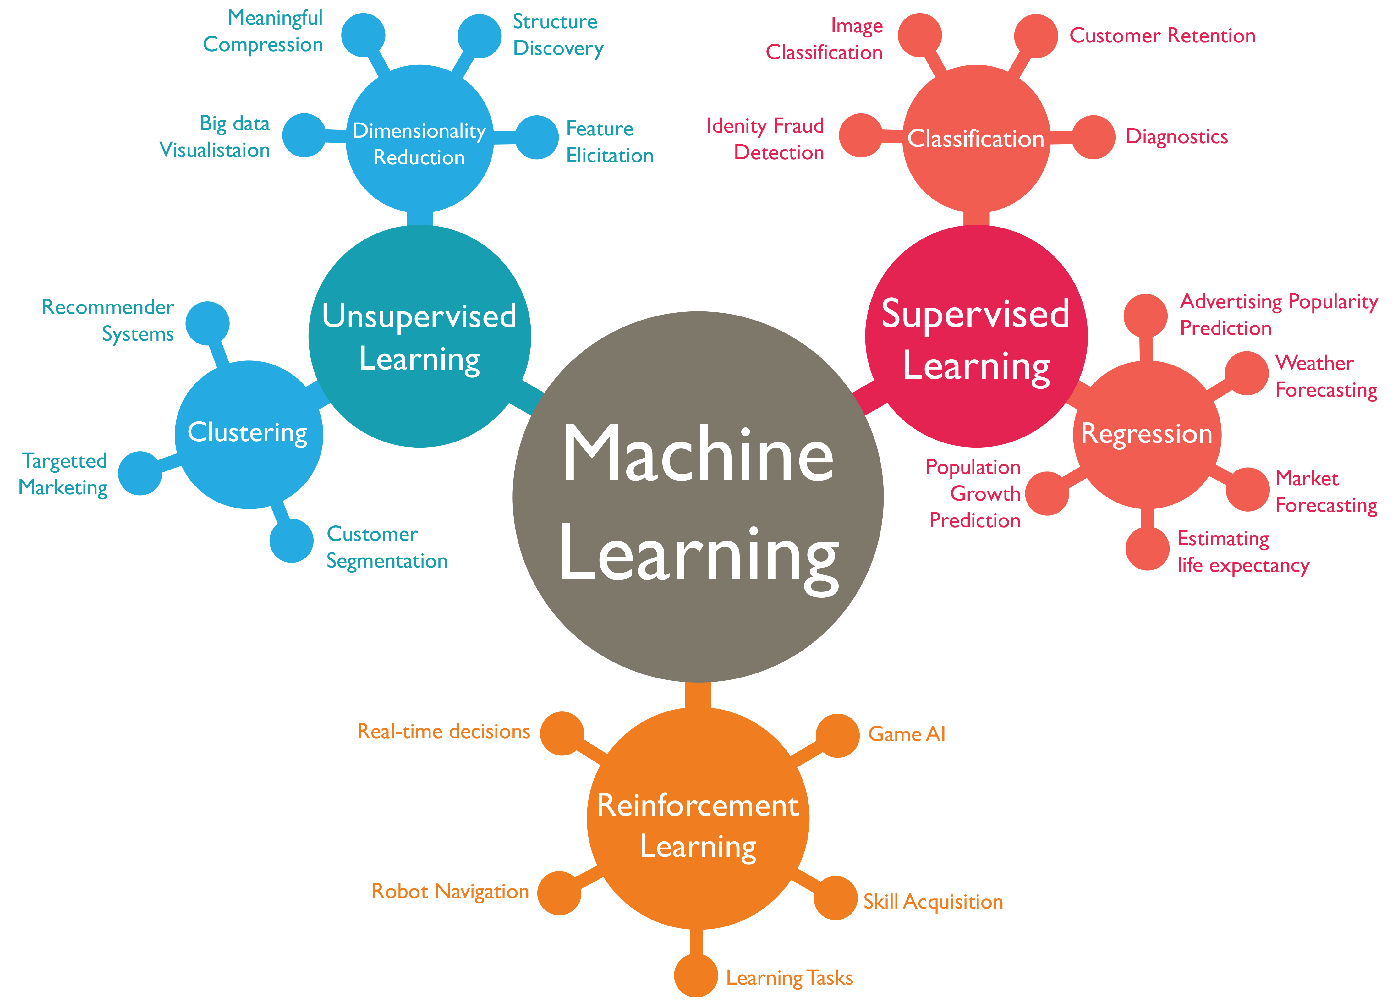

(https://github.com/shanmukh05/Machine-Learning-Roadmap

youtube: AI Warehouse - reinforcement learning)

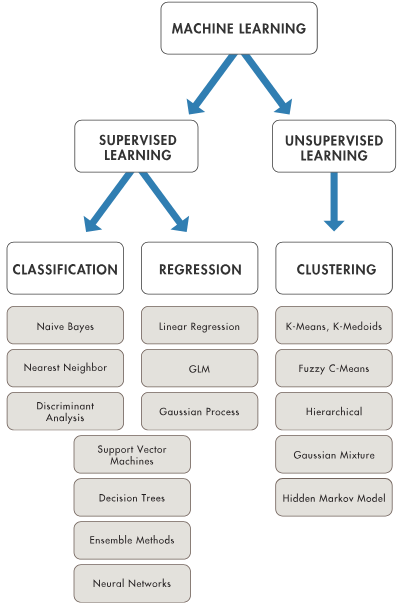

(https://www.mathworks.com/solutions/machine-learning.html)

#### Задача линейной регрессии в обозначениях статистики

В предыдущем семинаре был вектор $\vec{e}$ - вектор, который лежит в нуль-пространстве матрицы $A^T$, это та часть вектора $\vec{b}$, которая не может быть описана в рамках модели $A\vec{x}=\vec{b}$. 

$\vec{e}=\vec{b} - \vec{p}$, где $\vec{p} = AA^{\dagger}\vec{b}$ - наиболее близкий (в терминах квадратичного отклонения) к $\vec{b}$вектор, лежащий в пространстве столбцов матрицы $A$. Если $\vec{b}$ изначально лежит в пространстве столбцов $C(A)$ (и все столбцы линейнонезависимы), то $AA^{\dagger}\vec{b}=\vec{b}$, наша модель описывает данные полностью, без ошибки.

Теперь появляется случаяная составляющая, вектор $\vec{e}$ будет иметь случайную природу. 

Будем пользоваться принятыми в статистике обозначениями.

Теперь:   $\vec{b} \Longrightarrow \vec{y} ,\vec{a}\Longrightarrow \vec{\beta}, \vec{a}^* \Longrightarrow \vec{b},\vec{t} \Longrightarrow \vec{x}, A \Longrightarrow X$

$\vec{Y}$ - зависимая переменная, 

$X$ - матрица независимых переменных (предикторов), в ней первый столбец - единичный, он учитывает постоянное смещение, это, так называемая **dummy variable**

$\vec{\beta}$ - это истинные значения параметров модели, 


$$\vec{Y} = X\vec{\beta} +\vec{\epsilon}$$


$\vec{\epsilon}$ - случайный вектор ошибки. 

Основное предположение, что $\mathbb{E}[\vec{\epsilon}]=\vec{0}$, то есть ошибка является несмещенной.

Например, $\vec{Y} =[\vec{I},\vec{X} ][ \matrix{\beta_0 \cr  \beta_1}] + \vec{\epsilon}$ - для линейной регрессии первого порядка, $\vec{I}$ - вектор, состоящий из единиц (в отличие от единичной матрицы $I$)

В выражении для выходное переменной, случайной является только вектор ошибки

Производя регрессионный анализ (обучение регрессионной модели) мы получаем вектор $\vec{b}$


$$\vec{b}=(X^TX)^{-1}X^T\vec{Y}=X^{\dagger}\vec{Y}$$
 

 $\vec{b}$ - вектор коэффициентов регрессионной модели, которые отличаются  от истинных коэффициентов $\vec{\beta} $ из-за наличия погрешности в исходных данных, вектор $\vec{b}$ является оценкой истинного набора параметров нашей модели. 

$\vec{b}=X^{\dagger}\vec{Y}=X^{\dagger} X\vec{\beta} +X^{\dagger} \vec{\epsilon}=\vec{\beta} +X^{\dagger} \vec{\epsilon}$ ( так как $X^{\dagger}X=(X^TX)^{-1}X^TX=I$)

Так как $\mathbb{E}[\vec{\epsilon}]=\vec{0}$, то $\mathbb{E}[\vec{b}]=\vec{\beta}$, то есть, проведя, достаточное количество регрессий мы в среднем получим  истинные параметры.

Матрица $H=X(X^TX)^{-1}X^T$- это "hat-matrix",  потому что она надевает шапку на вектор $\vec{Y}$

$\hat{\vec{Y}}=HY=X(X^TX)^{-1}X^T\vec{Y}=X\vec{b}$, соотвественно $\hat{\vec{Y}}$ - это значения зависимой переменной, рассчитанные в рамках нашей модели. После обучения, мы можем использовать полученную модель для предсказаний, то есть, мы можем использовать полученные параметры регрессий для расчета вектора $\vec{Y_1}$который будет соотвествовать новым значениям предикторов $X_1$

Попробуем это в эксперименте на простом примере линейной регрессии с двумя параметрами (фитинг прямой линией)

clearvars
N=10; % размер выборки
tests_number = 76; % количество тестов
beta = [2; 5]; % истинные значения параметров
X1 = linspace(-1,1,N)';
X = [ones(N,1),X1]; % матрица предикторов
distrib = 'Normal'; % выбираем тип генератора случаных чисел 
delta = 0.973; % параметр дисперсии ошибки
b_mat = zeros(tests_number,2); % матрица, в которой мы будем сохранять результаты тестов
Yo = X*beta;
Y_points = repmat(Yo,[1 tests_number]);
for ii=1:tests_number
    pd = make_dist(distrib,mu=0,sig=delta^2); %генерит генератор случайных чисел 
    Y = Yo + delta*pd(N); % генерим данные как истинное значение модели + случайная ошибка
    %std(Y) % стандартное отклонение примерно равно заданной амлитуде ошибки
    b_mat(ii,:) = transpose(X\Y);
    Y_points(:,ii) = Y;
end
% табличка для отображения результатов
tb = table(beta(:),mean(b_mat)',std(b_mat)', ... вторая колонка таблицы - среднее значения коэффициентов по всем испытаниям
    'VariableNames', ...
    ["Истинные значения","Средние ", ...
    "Стандартное отклонение"], ...
    'RowNames', ...
    ["b_0" "b_1"])

%%% графики
disp("Точки - данные по котором производилась регрессия, каждый цвет - свой тест, прямые - результат фитинга")
fitted_distr_array = arrayfun(@(jj)fitdist(b_mat(:,jj),"Normal"),1:2);
ax = get_next_ax();
iteration_step = 1;% строим каждый 
inds = 1:iteration_step:tests_number;% будем шагать по номерам тестов
Cmat = rand([numel(inds),3]);% матрица цветов
X1 = X(:,2);
hold(ax,"on")
 for ii=inds
    Y = Y_points(:,ii); % генерим данные как истинное значение модели + случайная ошибка
    %std(Y) % стандартное отклонение примерно равно заданной амлитуде ошибки
    p1 = scatter(ax,X1,Y);
    p1.MarkerEdgeColor = Cmat(1+(ii-1)/iteration_step,:);
    p1.MarkerFaceColor = Cmat(1+(ii-1)/iteration_step,:);
    p1.MarkerFaceAlpha = 0.6;
    Ycalc = X*b_mat(ii,:)';
    p1 = plot(ax,X1,Ycalc,"LineWidth",1);
    p1.Color = Cmat(1+(ii-1)/iteration_step,:);
 end
 xlabel("X")
 ylabel("Y")
 hold(ax,"off")

% выбираем параметр, для которого отображается распределение
% фитинг 

selection = 1;
scatter(1:tests_number,b_mat(:,selection))
b_str = "b_"+ string(selection-1);
ylabel(b_str);xlabel("Номер розыгрыша")

ax = get_next_ax();
fitted_distr = fitted_distr_array(selection); % фитим распределения методом из statistical toolbox
plot(ax,fitted_distr) 
 title(ax,"Плотность вероятности "+ b_str)
 xlabel(ax,b_str);
 ylabel(ax,"pdf");

Тут важный момент, что для ошибки мы сделали только одно предположение, что она несмещенная, мы не полагали конкретной формы распределения.

Среднее по тестам значение нашей оценки параметров модели равно истинному значению 

[sampling_volume,tests_number,beta_mat] = sampling_surf_plot(beta,101,201,0.2);

% изучим влияние объема выборки на вариацию параметров
b_mat_selected = beta_mat(:,:,selection);
selection_var= (b_mat_selected - beta(selection)).^2;
bmin = min(b_mat_selected,[],'all');
bmax = max(b_mat_selected,[],'all');
ax = get_next_ax();
[Xsurf,Ysurf]= meshgrid(sampling_volume(:),tests_number);
surf(ax,Xsurf,Ysurf,selection_var');%,"LevelList",linspace(bmin,bmax,5))
xlabel("Объем выборки")
ylabel("Номер теста")

% строим зависимость вариации параметров модели от амплитуды ошибки
selection = 2;
b_str = "b_"+ string(selection);
ax = get_next_ax();
delta = [0.1,0.2,0.4,1]
b_std = cell(numel(delta),1);

hold(ax,"on")
for ii = 1:numel(delta)
    [~,~,beta_mat] = sampling_surf_plot(beta,101,201,delta(ii));
    b_mat_selected = beta_mat(:,:,selection);
    b_std{ii}=std(b_mat_selected,0,2);
    plot(ax,sampling_volume,b_std{ii},"LineWidth",3);
end
hold(ax,"off")
lgd = legend(ax,string(delta(:)),"Location",'northeast');
lgd.Title.String = "\Delta ";
xlabel(ax,"Объем выборки");
ylabel(ax,"std("+b_str+")");

ax = get_next_ax();
hold(ax,"on")
for ii = 1:numel(delta)
    [~,~,beta_mat] = sampling_surf_plot(beta,101,201,delta(ii));
    b_mat_selected = beta_mat(:,:,selection);
    b_std{ii}=std(b_mat_selected,0,2);
    plot(ax,sampling_volume,b_std{ii}/delta(ii),"LineWidth",3);
end
title("Нормированное на вариацию ошибки")
hold(ax,"off");
lgd = legend(ax,string(delta(:)),"Location",'northeast');
lgd.Title.String = "\Delta ";
xlabel(ax,"Объем выборки");
ylabel(ax,"std("+b_str+")/\Delta");

Основной экспериментальный вывод, вариация коэффициентов регрессии прямо пропорциональна амлитуде ошибки исходных данных

**Обозначения статистических параметров**

Случайные величины, которые мы изучаем путем их розыгрыша (сэмплирования, выборки) характеризуются векторами этих сэмплов

Пусть, вектора $\vec{X}$и $\vec{Y}$ - вектора сэмплов случайно величины, N - количество измерений.

$\overline{X} = \vec{I}^T\vec{X}/N$, $\overline{Y} = \vec{I}^T\vec{Y}/N$ - среднее значение выборки, $\vec{I}$ - вединичный вектор (состоящий из единиц)

Квадратичные отклонения:


$$S_{XY}=[\vec{X} - \overline{X}\vec{I}]^T[\vec{Y} - \overline{Y}\vec{I}]=\vec{X}^T\vec{Y}-N \overline{X} \overline{Y}$$
 


$$S_{XX}=[\vec{X} - \overline{X}\vec{I}]^T[\vec{X} - \overline{X}\vec{I}]=\vec{X}^T\vec{X}-N \overline{X} ^2$$
 

Это по сути скалярное произведение, только каждый из векторов смещен оносительно своего среднего

Черточка сверху- среднее значение, стрелочка сверху - вектор.

$Var(\vec{X}) =S_{XX}/(N-1)$ - вариация,

Если сложить данные в матрицу $M=[\vec{X},\vec{Y}]$, то ковариация этой матрицы (это ковариация двух случайных скалярных величин, которые даются в виде вектор-столбцов их семплов, это не случайные вектора!) будет :


$$Cov(M)=[\vec{X},\vec{Y}][\matrix{\vec{X}^T\cr \vec{Y}^T}]=[\matrix{S_{XX}& S_{XY} \cr S__{YX} & S_{YY} }]/(N-1)$$


Таким образом, в матрице ковариации выборок двух случайных переменных на диагонали стоят вариации каждой из переменных, а вне диагонали ковариации.

clearvars
N=3;
X=randn(N,1);Y=randn(N,1);
cov([X,Y])
cov(X,Y)
X=X-mean(X);Y=Y-mean(Y);
[X'*X,Y'*X;
    X'*Y,Y'*Y]/(N-1)

Если случаные переменные некоррелированы, то их ковариация должна быть близка к нулю. Если коррелированы, то нет. Проведем простой эксперимент с бросанием монетки. 

У нас есть две монетки. Пусть орел  - это 1 , а решка 0. 

disp("Монетки независимы, ковариация равна нулю:")
clearvars
x1 = rand(1000,1)>0.5;
x2 = rand(1000,1)>0.5;
Sxy=(x1'*x2)/(999)
%Sxy=(x1-mean(x1))'*(x2-mean(x2))/(999)

clearvars
disp("Монетки склеены разноименными краями, ковариация не равна нулю:" )
x1 = rand(1000,1)>0.5;
x2 = ~x1;
%Sxy=(x1-mean(x1))'*(x2-mean(x2))/(999)
Sxy=(x1'*x2)/(999)

Как так-то?

**Регрессионная модель  нулевого порядка**

$X_{zero \ order}=[\vec{I}]$ - матрица предикторов состоит только из одного единичного столбца

 
$$\vec{b}=b_0=(X^TX)^{-1}X^T\vec{Y}=(\vec{I}^T\vec{I})^{-1}\vec{I}^T\vec{Y}=\frac{\sum_{i=1}^{N}y_i}{\sum_{i=1}^{N}1}=\frac{\sum_{i=1}^{N}y_i}{N}=\overline{Y}$$


Таким образом,  регреcсия нулевого порядка описывает зависимость $Y $от $X$ как среднее от имеющихся результатов наблюдения Y.

**Первый порядок (прямая линия)**

Матрица модели состоит всего из двух столбцов: $X_{first \ order}=[\vec{I},\vec{X}]$, соотвественно, $X_{first\ order}^T=[\matrix{\vec{I}^T\cr \vec{X}^T}]$ (напомню, что стрелочка в $\vec{a}$, обозначает всегда вектор-столбец) 

Обратим внимание, что $\vec{I}^T\vec{X}=N\overline{X}$,где черточка сверху $\overline{X}$ обозначает среднее арифметическое значение столбца.

 
$$\vec{b}=[\matrix{b_0\cr b_1}]=X_{first  \ order}^{\dagger}\vec{Y}=([\matrix{\vec{I}^T\cr \vec{X}^T}][\vec{I}, \vec{X}])^{-1}[\matrix{\vec{I}^T\cr \vec{X}^T}]\vec{Y}=([\matrix{N \ &  \vec{I}^T\vec{X} \ \cr \vec{X}^T\vec{I} & \vec{X}^T\vec{X}}])^{-1}[\matrix{\vec{I}^T\cr \vec{X}^T}]\vec{Y}$$


Учитывая, что (см) $\vec{X}^T\vec{X}=S_{XX}+N\overline{X}^2 $, а (см) $\vec{X}^T\vec{Y}=S_{XY}+N\overline{X}\overline{Y}$:

 
$$\vec{b}=[\matrix{N \ &  N\overline{X} \ 
            \cr N\overline{X} &S_{XX}+N\overline{X}^2 }]^{-1}   [\matrix{N\overline{Y} \cr S_{XY}+N\overline{X}\overline{Y}}]$$


| Обратную матрицу довольно легко инвертировать, формула для инвертирования матрицы 2х2 

$A^{-1}=[\matrix{a_{11} & a_{12} \cr a_{21} & a_{22}}]^{-1}=\frac{1}{det(A)}[\matrix {a_{22} & -a_{12} \cr -a_{21} & a_{11}}]$, где определитель $det(A) = a_{11}a_{22} - a_{21}a_{12} $

A=sym("a",[2 2]); 
inv(A)
det(A)
inv(A)*det(A)


$$det(X_{first \ order}^TX_{first \ order})=N\vec{X}^T\vec{X}- (\vec{I}^T\vec{X})^2 =N\vec{X}^T\vec{X}- (N \overline{X})^2=NS_{XX}$$


Тогда, с учетом формулы выше  (см) окончательно получим выражение для коэффициентов аппроксимации:


$$[\matrix{b_0\cr b_1}] =\frac{1}{N} S^{-1}_{XX} [\matrix{S_{XX}+N\overline{X}^2   \ &  -N\overline{X} \ \cr -N\overline{X}&  N }][\matrix{N\overline{Y}\cr S_{XY}+N\overline{X}\overline{Y}}]$$


Отсюда получаем очень простые выражения для коэффициентов аппроксимации:


$$b_1=\frac{1}{N} S^{-1}_{XX} [-N^2\overline{X}\overline{Y} + NS_{XY} + N^2\overline{X}\overline{Y}]=S^{-1}_{XX}{S_{XY}}$$



$$b_0=S^{-1}_{XX}[NS_{XX}\overline{Y}+N^2 \overline{X}^2 \overline{Y} - NS_{XY}\overline{X}-N^2   \overline{X}^2 \overline{Y}  ]=\overline{Y} - {S_{XX}^{-1}S_{XY}}\overline{X}=\overline{Y}-b_1\overline{X}$$


% проверка правильности выражений для расчета через ковариции и через
% псевдообратную матрицу
clearvars
N = 10
X = linspace(-1,1,N)';
Y = 0.0 + 0.43*X + 0.01*randn(10,1);
% через встроенную функцию:
Kxy = cov(X,Y) % матрица ковариации двух случайных переменных, представленных векторами их семплов одинаковго размера
% матричное выражение
[X,Y]'*[X,Y]/(N-1) % матрица ковариации двух случаных переменных X и Y
b1 = Kxy(1,2)/Kxy(1,1);
b0=mean(Y)-b1*mean(X);
b_vect_cov = [b0;b1] % через матрицу ковариации
% расчет через псевдообратную матрицу
I = ones(size(X));
b_vect_pseudoInverse = [I,X]\Y


$$\vec{\hat{Y}}=[\vec{I},\vec{X}] [\matrix {b_0\cr b_1}]=\vec{I}\overline{Y}-b_1\vec{I}\overline{X} + b_1\vec{X}$$



$$\vec{\hat{Y}} - \vec{I}\overline{Y}=b_1[\vec{X}-\vec{I}\overline{X}]={S_{XX}^{-1}S_{XY}}[\vec{X}-\vec{I}\overline{X}]$$


Формула расчета параметров модели через вариацию-ковариацию для линейной регрессии справедлива и для общего случая (когда у нас имеются несколько предикторов). Задача тогда формулируется как:


$$\vec{Y}=[\vec{I},\vec{X_1},\dots,\vec{X_P}][\matrix{b_0 \cr \vec{b_1} }]=[\vec{I},X][\matrix{b_0 \cr \vec{b_1} }]$$


Вектор параметров модели также дается выражением:


$$\vec{b_1}=S^{-1}_{XX}\vec{S}_{XY}$$



$$b_0=\overline{Y} - \vec{\overline{X}}^T\vec{b_1}$$


Однако, теперь:


$$S_{XX}=(X-\vec{I}\vec{\overline{X}}^T)^T(X-\vec{I}\vec{\overline{X}}^T)=X^TX - N\vec{\overline{X}}\vec{\overline{X}}^T=(N-1)Cov(X)$$



$$\vec{S}_{XY}=X^T\vec{Y}-N\vec{\overline{X}}\overline{Y}$$


$\vec{\overline{X}}$ - вектор-столбец средних значений предикторов. Подробный вывод см. отдельно.

clearvars
N=10
X1 = randn(N,1);
X2= randn(N,1);
I = ones(size(X1));
Y = 0.5 + 0.43*X1 + 0.61*X2+ 0.2*randn(N,1);
meanY=mean(Y)
X = [X1,X2];
meanX = I*mean(X)

Sxy = (X-meanX)'*(Y-meanY)

Sxx = (X-meanX)'*(X-meanX)

cov(X)*(N-1)
b1 = Sxx\Sxy;
b0=mean(Y)-mean(X)*b1

b_vect_cov = [b0;b1]
b_vect_pseudoInverse= [I,X]\Y

Альтернативный вариант  - через матрицу ковариации всех переменных:


$$Cov([X,\vec{Y}]) =\frac{1}{N-1} [\matrix{(N-1)Cov(X)& \ \vec{S}_{XY} \cr \vec{S}_{XY}^T & S_{YY}} ]$$


clearvars
N=100
X1 = randn(N,1);X2= randn(N,1);Y = 0.5 + 0.43*X1 + 0.61*X2+ 0.2*randn(N,1); % генерим исходные данные
X = [X1,X2];
M = [X,Y]; % складываем все в одну табличку (матрицу свойств)
CovM = cov(M) % считаем ее ковариацию
b1_vec = CovM(1:2,1:2)\CovM(1:2,end) % находим коэффициенты предикторов
b0=mean(Y) - mean(X)*b1_vec % нашли dummy variable
% для сравнения тоже самое по формулам линейной алгебры:


#### Матрица ковариации параметров модели

Теперь вернемся к линейной регресси 


$$\vec{b}=X^{\dagger}\vec{Y}=X^{\dagger}X\vec{\beta} + X^{\dagger}\vec{\epsilon}=\vec{\beta} + X^{\dagger}\vec{\epsilon}$$


$\mathbb{E}[\vec{b}]=\vec{\beta}$, так как $X^{\dagger}X=(X^TX)^{-1}X^TX=I$, а $\mathbb{E}[\vec{\epsilon}]=\vec{0}$


$$Cov(\vec{b})=(\vec{\beta}-\vec{b})(\vec{\beta}-\vec{b})^T=((X^{\dagger}X-I)\vec{b} + X^{\dagger}\vec{\epsilon})((X^{\dagger}X-I)\vec{b} + X^{\dagger}\vec{\epsilon})^T=X^{\dagger}\vec{\epsilon}\vec{\epsilon}^T(X^{\dagger})^{T}$$



$$X^{\dag}Cov(\vec{\delta})X^{\dag^T}$$


Теперь воспользуемся тем, что вектор ошибки случайный и каждая точка независима от другой, и все они получены из нормального распределения  $\delta \sim \sigma^2 N(0,1)$  - означает, что $\delta$ получен из нормального распределения со средним значением равным нулю. Тогда ковариации будет диагональной: $Cov(\vec\delta)=[\matrix {\sigma^2 &...& 0\cr
0&\ddots&0\cr 0 &\dots &\sigma^2}]$


$$X^{\dag}Cov(\vec{\delta})X^{\dag^T}{}=X^{\dag}X^{\dag^T}{}\sigma^2=(X^TX)^{-1}\sigma^2$$


Последниц переъод следует из:


$$X^{\dag}X^{\dag^T}=(X^TX)^{-1}X^T[(X^TX)^{-1}X^T]^T=(X^TX)^{-1}X^TX[(X^TX)^{-1}]^T=[(X^TX)^{-1}]^T=(X^TX)^{-1}$$


Таким образом, окончательно получим выражение для матрицы ковариации параметров линейной регрессии:


$$Cov(\vec{\beta)}=(X^TX)^{-1}\sigma^2$$


В этой формуле мы использовали то, что ошибка распределена нормально и для каждой точки дисперсия этого распределения одинакова.

Матрица ковариации вектора параметров линейной регрессии


$$Cov(\vec{Y}_{interp})=X_{interp}Cov(\vec{\beta})X_{interp}^T$$


#### Небольшой численный эксперимент на предмет того, что такое доверительная вероятность.

% проведем численный эксперимент на выполнение статистики
clearvars
M = 1000;% количество тестов
N = 100;% количество точек в выборке
beta2 = zeros(M,2);
P=2;% количество параметров регрессионной модели
for jj = 1:M
    x = randn(N,1);
    y = 1 + 2*x + randn(N,1);
    X = [ones(N,1),x];
    beta = X\y;
    e= X*beta - y;
    sigma = e'*e/(N-P);% считаем вариацию ошибки
    Cov_beta = (X'*X)\eye(P)*sigma;% считаем матрицу ковариации 
    Var_beta = diag(Cov_beta);% считаем вариацию (диагональные элементы матрицы ковраиации)
    beta2(jj,:)=beta(2) + sqrt(Var_beta(2))*[1 -1];
end
sum((2<=beta2(:,1)) & (2>=beta2(:,2)))/M
d = fitdist(beta2(:,2),"Normal")
plot(d)

### Проблема мультиколлинеарности и перебоучения, уменьшение размерности при помощи метода анализа главных компонент

Для примера рассмотрим последовательность работы PCA + линейная регрессия

Общая стратегия применения метода анализа главных компонент

- Разбиваем исходные данные на обучающую выборку и выборку для тестирования обученной модели 

- Проводим анализ "лишних" данных и выкидываем их при помощи метода анализа главных компонент

- Обучаем регрессионную модель на обучающей выборке

- Преобразуем данные для тестирования в базис ортогональной системы координат главных компонент

- Рассчитываем прогноз при помощи обученной модели

#### Пример линейной регрессии с методом анализа главных компонент (LinReg + PCA)

Первый этап - загрузка и обработка данных. 

В настоящее время для работы с данными большого объема большое распространение получил HDF5 (**Hierarchical Data Format**). Изначально разрботан для суперкомпьютерных вычислений, в настоящее время поддерживается некоммерческой организацией HDF Group.

Это бинарный формат , который позволяет хранить данные в структурированном виде. Можно сказать, что это одна из попыток стандартизировать работу с большими данными в различных системах научных расчетов (matlab,julia,python,R), так и в языках общего назначения.

Содержит иерархию из двух основных типов объектов:

- Datasets — наборы данных, многомерные массивы объектов одного типа

- Groups — группы, являются контейнерами для наборов данных и других групп (по сути это папки)

Содержимое файлов HDF5 организовано подобно  файловой системе, для доступа к данным применяются пути, сходные с POSIX-синтаксисом, например, */path/to/resource*. Метаданные хранятся в виде набора именованных атрибутов объектов. Данные могут хранится в сжатом виде.

Внутрениий формат данных матлаба - mat-файлы, начиная с версии 7.3 основаны на формате HDF5. 

Воспользуемся встроенной в лискрипт утилитой для загрузки файла. В качестве примера будем пользоваться некоторыми метеорологическими данными из открытого источника ([Bottle Database – CalCOFI](https://calcofi.org/data/oceanographic-data/bottle-database/)). Они были загружены в формате csv и потом пересохранены в формат hdf5. 

play_with_hdf5 = false; % эту галочку надо установить, если хочется поиграться с "сырыми" данныим
% по умолчанию загружаются уже "просеянные" данные, сохраненные в мат-файле
if play_with_hdf5

% Create a structure to store imported HDF5 data
data = struct();

% Open HDF5 file
fileID = H5F.open("E:\projects\datasets\bases\bottle\bottle.h5");

data.Datasets(1).Name = "BtlNum";
dsID1 = H5D.open(fileID, "/BtlNum");
data.Datasets(1).Value = H5D.read(dsID1);

data.Datasets(2).Name = "Depthm";
dsID2 = H5D.open(fileID, "/Depthm");
data.Datasets(2).Value = H5D.read(dsID2);

data.Datasets(3).Name = "NO2uM";
dsID3 = H5D.open(fileID, "/NO2uM");
data.Datasets(3).Value = H5D.read(dsID3);

data.Datasets(4).Name = "O2ml_L";
dsID4 = H5D.open(fileID, "/O2ml_L");
data.Datasets(4).Value = H5D.read(dsID4);

data.Datasets(5).Name = "R_Depth";
dsID5 = H5D.open(fileID, "/R_Depth");
data.Datasets(5).Value = H5D.read(dsID5);

data.Datasets(6).Name = "R_PHAEO";
dsID6 = H5D.open(fileID, "/R_PHAEO");
data.Datasets(6).Value = H5D.read(dsID6);

data.Datasets(7).Name = "R_SALINITY";
dsID7 = H5D.open(fileID, "/R_SALINITY");
data.Datasets(7).Value = H5D.read(dsID7);

data.Datasets(8).Name = "STheta";
dsID8 = H5D.open(fileID, "/STheta");
data.Datasets(8).Value = H5D.read(dsID8);

data.Datasets(9).Name = "Salnty";
dsID9 = H5D.open(fileID, "/Salnty");
data.Datasets(9).Value = H5D.read(dsID9);

data.Datasets(10).Name = "T_degC";
dsID10 = H5D.open(fileID, "/T_degC");
data.Datasets(10).Value = H5D.read(dsID10);


% Close HDF5 datasets and clear variables used to store the dataset IDs
H5D.close(dsID1)
clear dsID1
H5D.close(dsID2)
clear dsID2
H5D.close(dsID3)
clear dsID3
H5D.close(dsID4)
clear dsID4
H5D.close(dsID5)
clear dsID5
H5D.close(dsID6)
clear dsID6
H5D.close(dsID7)
clear dsID7
H5D.close(dsID8)
clear dsID8
H5D.close(dsID9)
clear dsID9
H5D.close(dsID10)
clear dsID10

% Close HDF5 file
H5F.close(fileID)
clear fileID

% Display results
data

Формируем таблицу данных

all_data = data.Datasets
all_data_names = arrayfun(@(x)x.Name,all_data);
all_data_cell= arrayfun(@(x)(x.Value),all_data,"UniformOutput",false);
all_data_mat = cat(2,all_data_cell{:});
flag = any(isnan(all_data_mat),2)|any(all_data_mat==-1,2);% находим строки таблицы, содержащие NaN'ы
data_mat = all_data_mat(~flag,:);% удаляем эти строки
else
    data = load(fullfile(get_folder(),"bottle.mat"));
    data_mat = data.data_mat;
    all_data_names = data.all_data_names;
end
data_table = array2table(data_mat,VariableNames=all_data_names)

Можно посмотреть на данные в файле

x_var_index = 7;
y_var_index = 4;
ax = get_next_ax();
scatter(ax,data_table,x_var_index,y_var_index,"filled","AlphaData",0.5)
grid(ax,"on")

Формирование обучающей выборки и выборки для тестирования модели

dependent_variable = all_data_names(10) % выбираем зависимую переменную, которую будем предсказывать
train_data_fraction=0.78;% доля исходных данных, которые идут на обучение
row_number = size(data_mat,1);
train_indices = 1:floor(row_number*train_data_fraction);% индексы тех строк, которые идут на обучение
test_indices = train_indices(end):row_number;% строки текстовой выборки
Y = data_table.(dependent_variable); % массив всех данных для выбранной переменной
flag = all_data_names~=dependent_variable;flag(1)=false;
X = table2array(data_table(:,flag)); % в предикторы идут все столбцы кроме столбца зависимой переменной и первого столбца (с индексами)
% формируем матриы выборок
YTrain = Y(train_indices);YTest = Y(test_indices);
XTrain = X(train_indices,:);XTest = X(test_indices,:);

Главные компоненты для матрицы предикторов обучающей выборки находим SVD разложением:


$$X_{train}=U\Sigma V^T=\Sigma_{i=1}^r\sigma_i\vec{u_i}\vec{v_i}^T$$


Напомню, что марица U - это ортонормированный базис пространства  столбцов, а $V$ - ортонормированный базис пространства строк. Значения $\sigma_i$ - это сингулярные значения, отсортированные в порядке убывания, $r$ - ранг матрицы. Последняя форма записи сингулярного разложения - представляет исходную матрицу в виде суммы одноранговых матриц отсортированных в порядке их "вклада" в общую матрицу. 

mu_svd = mean(XTrain) % средние значения по каждому из столбцов
[U,S,V] = svd(XTrain -mu_svd,'econ'); % X = U*S*V'

Когда функция svd вызывается с признаком `econ` это означает, что она возвращает матрицы уменьшенной размерности, если $X_{train}$ - матрица размером mxn, то для m > n рассчитываются только первые n столбцов матрицы $U$, а  S  - это матрица nxn. Таким образом из матрицы сингулярных векторов выкидываются все нулевые сингулярные вектора и она становится диагональной.

US = U*S; % дальше эти матрицы будут нужны в виде произведения (отдельные матрицы не нужны)
100*diag(S.^2)/sum(diag(S.^2)) % отношение квадратов сингулярных значений показывает долю вариации 
% исходных данных, окторую объясняет каждая из компонент
norm((XTrain-mu_svd) - US*V') % убеждаемся, что формула сингулярного разложения работает

Операция умножения исходной матрицы на левые сингулярные вектора приводит ее к нормированному базису:


$$X_{train}V=U\Sigma$$
 

Матрица, которая стоит в равенстве справа - это ортогональная матрица (так как $(U\Sigma)^TU\Sigma=\Sigma^TUU^T\Sigma=\Sigma^2$ - диагональная), но не ортонормированная, то есть, столбцы этой матрицы ортогональны, но их модули не равны единице. Далее в соответствии с методом анализа главных компонент и теоремой Экхарта-Янга, мы уменьшаем размерность задачи, то есть, оставляем от исходной матрицы предикторов только матрицу ранга $r'<r$. То есть, в сумме, стоящей вы выражении для сингулярного разложения справа, оставляем только первые $r'$ членов:

dimentionality = 5; % количество сингулярных значений (оно же размерность матрицы после 
% того как мы выкинем часть базисных векторов)
US_reduced = US(:,1:dimentionality);% уменьшаем размерность U*S
I = ones(size(US,1),1);

Решаем задачу регрессии - находим параметры модели (для линейной регрессии обучение состоит из одной итерации):

b =  [I,US_reduced]\YTrain

Раскладываем тестовые данные по базису правых сингулярных векторов 

US_test = (XTest-mean(XTest))*V(:,1:dimentionality);

Рассчитываем предсказание модели

I = ones(size(US_test,1),1);
Yprediction = [I,US_test]*b;
YTest - Yprediction;
ax = get_next_ax();
scatter(ax,YTest,Yprediction)
xlabel("YTest")
ylabel("YPrediction")
grid on

Посчитаем корреляцию предсказания и тестовых данных:


$$Cor(X,Y)=\frac{Cov(X,Y)}{\sigma_A\sigma_B$$


где $\sigma$ - стандартное отклонение ($\sigma_X=\sqrt{Cov(X)$), соотвественно когда мы смотрим матрицу корреляции между 

векторами сэмплов двух случаных величин, мы имеем симметричную матрицу, на диагонале которой стоят единицы, а офф-диагональные элементы дают коэффициенты корреляции, чем ближе коэффициент корреляции двух величин к единице, тем более они коррелированы.

corrcoef(YTest,Yprediction) %

Это был, относительно низкоуровневый подход, мы применяли базовые функции линейной алгебры - сингулярное разложение и mldivide (которое, как мы обсуждали, работает по методу QR-факторизации), сейчас попробуем сделать тоже самое, но при помощи более высокоуровневых функций.

Далее будем использовать statistical toolbox, в котором есть большой арсенал функций для машинного обучения, в том числе для регрессионного анализа.

Мы будем пользоваться двумя функциями:

`pca(Xtrain)` - функция для анализа данных методом главных компонент, Xtrain - это, соотвественно, матрица предикторов для обучающей выборки

`fitlm(scoreTrain,Ytrain)` - эта функция проводит обучение регрессионной модели на  обучащей выборке из матрицы предикторов `scoreTrain` и зависимой переменной `Ytrain` (это одна из колонок матрицы данных)

[coeff,scoreTrain,latent,tsquared,explained,mu] = pca(XTrain,"Centered",true);% coeff - это матрица V,

В качестве входного аргумента фугкции **pca** - матрица предикторов, опционально можно передавать алгоритм (по умолчанию используется `'svd'` , но может быть использован и алгоритм, основанный на спектральном разложении матрицы ковариации `'eig'`,  а также `'als'`, про последний написано, что он лучше работает с пропущенными значениями (например, `NaN`) ; `'centered'`, `true` - пара аргументов, которая показывает надо ли центрировать данные (вычитать средние)

Функция `pca` возвращает следующие переменные: `coeff,scoreTrain,latent,tsquared,explained,mu`. 

`coeff` - это матрица$V$сингулярного разложения

Выходной аргумент `scoreTrain` - это произведение $U\Sigma$.

`latent` - это вектор квадратов сингулярных значений (он же вектор собственных значений матрицы ковариации)

`tsquared` - Hotelling’s T-squared statistic is a statistical measure of the multivariate distance of each observation from the center of the data set.

`explained`  - показывает какую долю вариации (выражается в процентах) обясняет данная спектральная компонета. Как показано выше, по сути доля вариации - это квадрат сингулярного значения номированный на сумму квадратов всех сингулярных значений.

mean(coeff./V)
mean(US./scoreTrain)
transpose(sort(eig((XTrain-mu)'*(XTrain-mu)),"descend")/size(US,1)) % считаем через собственные значения матрицы ковариации
transpose(diag(S*S)./latent/(size(US,1)))
transpose(100*(diag(S.*S)./sum(diag(S.*S)))./explained) % показывает в процентах объясняемую данной матрицей долю вариации

Смотрим какое число сингулярных значений объясняет 95 процентов вариации:

idx = find(cumsum(explained)>99,1)

Обучаем регрессионную модель на тренировочных данных, в которых была уменьшена размерность.

scoreTrain95 = scoreTrain(:,1:idx);
mdl = fitlm(scoreTrain95,YTrain)
scoreTest95 = (XTest-mu)*coeff(:,1:idx);

Дальше мы испльзуем обученную модель  `mdl для того, чтобы предсказать значения в текстовой выборке, для этого используется функция predict, в которую в качестве первого аргумента передается обучнная модель, а в качестве второго - новая матрица предикторов:` 

YTest_predicted = predict(mdl,scoreTest95);
norm(YTest_predicted - Yprediction) 
% расхождение между предсказаниями statistics toolbox и расчету 
% при помощи базовых функций линейной алгебры

#### Пример использования метода анализа главных компонент с картинками

Мы любим примеры с картинками, поэтому попробуем, применить линейную регрессию для предсказания куска картинки. Теперь наше регрессионное уравнение будет иметь вид:


$$Y=XB+E$$


Сверху над $Y, B,E$ пропали стрелочки, так как теперь это матрицы

Столбцы матрицы $B$ - это вектора коэффициентов линейной регрессии, i-й столбец, соответственно, описывает нам i-й столбец матрицы Y. Для каждого столбца матрицы отклика мы находим вектор-столбец параметров линейной регрессии.

Будем рассматривать задачу следующим образом. Разделим картинку на четыре части

левая верхняя - будет матрица предикторов обучающей выборки (матрица $X$)

правая верхняя - матрица откликов (матрица $Y$)

левая  нижняя часть - матрица предикторов тестовой выборки ($X_{test}$ )

правая нижняя часть - матрица отклика тестовой выборки

Наша задача состоит в том, чтобы не значая правую нижнюю часть картинки ее пресказать при помощи линейной регрессионной модели, которую мы обучем на обучающей выборке (то есть на верхней картинке)

clearvars
% Import image
folder =  get_folder();
selected_image= "test1.jpg"; % 
figs_folder =folder + "\figs"; 
full_file = fullfile(figs_folder,selected_image);
figs = imread(full_file);
M = size(figs,1)-2;N = size(figs,2)-2;

data= double((im2gray(figs))); 
cut_size = [1,354,755];
data = data(cut_size(1):end,cut_size(2):cut_size(3));
imshow(uint8(data))
ax =gca;
title(ax,"Исходная картинка")
M = size(data,1);
N = size(data,2);
t_dims = [91,197]; % размер тестовой картинки

% test_image_dimentions 
Mlast = M-t_dims(1)-1; % число строк в обучающйе выборке
Nlast = N-t_dims(2)-1;% число столбцов предикторов в обучающей выборке
XTrain =data(1:Mlast,1:Nlast); % формируем матрицу предикторов
YTrain =data(1:Mlast,(Nlast+1):end); % формируем матрицу зависимой переменной
XTest = data((Mlast+1):end,1:Nlast);
YTest = data((Mlast+1):end,(Nlast+1):end);

imshow(uint8(join_matrix(XTrain,YTrain,XTest,YTest,10,0)))
Itrain = ones(size(XTrain,1),1);
B1 = [Itrain,XTrain]\YTrain;
Ipred = ones(size(XTest,1),1);
Ypredicted1 =[Ipred, XTest]*B1;
disp("Линейная регрессия с уменьшением размерности матрицы предикторов:")
imshow(uint8(join_matrix(XTrain,YTrain,XTest,Ypredicted1,10,0)))
%imshow(mat2gray(join_matrix(XTrain,YTrain,XTest,Ypredicted1,10,0)))

Добавляем метод главных компонент, чтобы понизить размерность матрицы предикторов обучающей выборки

% combined with pca
[coeff,scoreTrain,~,~,explained,mu] = pca(XTrain);% coeff - это матрица V,
mu_svd = mean(XTrain);% средние значения по каждому из столбцов
%M= size(XTrain,1);
%N = size(XTrain,2);
[U,S,V] = svd(XTrain -mu_svd,'econ'); % X = U*S*V'
US = U*S;
MAX_S = size(S,1);

dimentionality = 4; % количество сингулярных значений
US_reduced = US(:,1:dimentionality);% уменьшаем размерность U*S
I = ones(size(US,1),1);
b =  [I,US_reduced]\YTrain;

Раскладываем тестовые данные по базису правых сингулярных векторов 

US_test = (XTest-mu_svd)*V(:,1:dimentionality);

Рассчитываем предсказание модели

I = ones(size(US_test,1),1);
Yprediction = [I,US_test]*b;
disp("Линейная регрессия без уменьшения размерности матрицы предикторов:")
imshow(uint8(join_matrix(XTrain,YTrain,XTest,Yprediction,10,0)))
%imshow(mat2gray(join_matrix(XTrain,YTrain,XTest,Yprediction,10,0)))

ЛИТЕРАТУРА

1. N.Draper, H.Smith . Applied regression analysis. Third edition. Wiley Series in Probability and Statistics. 

2.  Gilbert Strang - Introduction to Linear Algebra (2016, Wellesley-Cambridge Press)

3. John D'Errico (2025). Optimization Tips and Tricks (https://www.mathworks.com/matlabcentral/fileexchange/8553-optimization-tips-and-tricks), MATLAB Central File Exchange. Retrieved January 30, 2025.

### Выводы.

- Рассмотрели задачу линейной регрессии с точки зрения статистики. Основный аспекты терминологии: зависимая переменная ($Y$), матрица предикторов ($X$), тестовая и обучающая выборки, регрессионная модель.

- Путем анализа серии регрессий убедились, что средние значения параметров линейной регрессии $\vec{b}$стремится к истинным значениям модели $\vec{\beta}$ при условии, что матожидание ошибки равно нулю. Также установили, что вариация ошибки  приводит к вариации параметров регрессионной модели, причем, вариация  параметров оказывается прямо пропорциональной вариации ошибки.

- Сформулировали задачу линейной регрессии и получили выражения для коэффициентов модели через матрицу ковариации.

- Получили выражения для матрицы ковариации параметров регрессионной модели, которая может быть использована для расчета доверительного интервала параметров регрессионной модели. 

- На двух примерах посмотрели последовательность операций при применении метода анализа главных компонент в задаче линейной регресии для задач с одной выходной переменной и несколькими (multioutput linear regression). 

#### Вывод формулы для коэффициентов линейной регрессии через статистические параметры

**Дополнение Шура (Schur complement) и инвертирование блочных матриц **

Если у нас есть блочная матрица вида:

$M=[\matrix{A \ & \ B \cr C \ & \ D}]$ ( то есть, матрица, у которой элементы - матрицы соотвествующего размера)

дополнение Шура  $Sh = D-CA^{-1}B$


$$[\matrix{A \ & \ B \cr C \ & \ D}]^{-1}=[\matrix{A^{-1}+ A^{-1}BSh^{-1}CA^{-1} & -A^{-1}BSh^{-1} \cr -Sh^{-1}CA^{-1}
& Sh^{-1} } ]$$


Формула справедлива когда матрицы $Sh$ и $A$- обратимы

[https://www.cis.upenn.edu/~jean/schur-comp.pdf](https://www.cis.upenn.edu/~jean/schur-comp.pdf)

#### Матричная форма линейной регрессии в статистической терминологии

Матрица модели: $X_{M}=[\vec{I}, X]$, теперь $X$ - матрица предикторов (размером *NxP*)

 $\vec{b}=[\matrix{b_0\cr \vec{b_1}}]=X_{M}^{\dagger}\vec{Y}=([\matrix{\vec{I}^T\cr X^T}][\vec{I}, X])^{-1}[\matrix{\vec{I}^T\cr X^T}]\vec{Y}=([\matrix{N \ &  \vec{I}^TX \ \cr X^T\vec{I} & X^TX}])^{-1}[\matrix{\vec{I}^T\cr X^T}]\vec{Y}$(*)

Вначале обратим внимание на кросс-диагональные 

элементы блочной матрицы:


$$\vec{I}^TX \frac{1}{N}=[\sum_{i=1}^NX_{i1},...,\sum_{i=1}^{N}X_{ij},...,\sum_{i=1}^{N}X_{i,P}]/N=[\overline{X}_1,...,\overline{X}_P]=\vec{\overline{X}}^T$$
 

То есть, $\vec{\overline{X}}$ - это вектор размером *Px1*, элементами которого являются средние значения столбцов матрицы $X$. С учетом этого, выражение (*) удобней переписать в виде:


$$[\matrix{b_0\cr \vec{b_1}}]=X_M^{\dagger}\vec{Y}=[X_M^{T}X_M]^{-1}X_M^T\vec{Y}=([\matrix{N \ &  N\vec{\overline{X}}^T \ \cr N\vec{\overline{X}} & X^TX}])^{-1}[\matrix{N\overline{Y}\cr X^T\vec{Y}}]$$


Вначале рассмотрим блочную матрицу $X_M^{T}X_M=[\matrix{N \ &  N\vec{\overline{X}}^T \ \cr N\vec{\overline{X}} & X^TX}]$.

Согласно формуле Шура, блочная матрица  $M=[\matrix{A &B\crС &D}]$ может быть инвертирована через  дополнение Шура: $Sh = D-СA^{-1}B$, $M^{-1}=[\matrix{A^{-1}+ A^{-1}BSh^{-1}CA^{-1} & -A^{-1}BSh^{-1} \cr -Sh^{-1}CA^{-1}
& Sh^{-1} } ]$

Для нашей конкретной матрицы:

$A^{-1}=\frac{1}{N}$ (просто скаляр), $B=N\vec{\overline{X}}^T$(вектор-строка),$C=N\vec{\overline{X}}$(вектор-столбец), $D=X^TX$(матрица PxP)


$$[X_M^TX_M]^{-1}=[\matrix{ N^{-1} +N^{-1}N\vec{\overline{X}}^TSh^{-1}N\vec{\overline{X}}N^{-1} \ & -N^{-1}N\vec{ \overline{X}}^TSh^{-1}\cr -Sh^{-1}N\vec{\overline{X}}N^{-1} & Sh^{-1}}]=[\matrix{ N^{-1} +\vec{\overline{X}}^TSh^{-1}\vec{\overline{X}} \ & \vec{ \overline{X}}^TSh^{-1}\cr -Sh^{-1}\vec{\overline{X}} & Sh^{-1}}]$$



$$[\matrix{b_0\cr \vec{b_1}}]=[X_M^{T}X_M]^{-1}X_M^T\vec{Y}=[\matrix{ N^{-1} +\vec{\overline{X}}^TSh^{-1}\vec{\overline{X}} \ & \vec{ \overline{X}}^TSh^{-1}\cr -Sh^{-1}\vec{\overline{X}} & Sh^{-1}}][\matrix{N\overline{Y}\cr X^T\vec{Y}}]$$


Посмотрим внимательно на выражение для вектора параметров $\vec{b_1}$:


$$\vec{b_1} = Sh^{-1}[ X^T\vec{Y}-N\vec{\overline{X}}\overline{Y}]$$


Оно  напоминает выражение для $b_1$ из формулы для прямой линии, только там $b_1$ - это был скаляр. Выражение в квадратных скобках имеет похожий смысл, как и выражение для Sxy, там $\vec{X}$ и $\vec{Y}$ были векторами, а их средние значения - скалярами, теперь $X$ - это матрица,  $\vec{\overline{X}}$ - вектор-столбец средних значений матрицы $X$ в каждом из столбцов. $X^T\vec{Y}$ - вектор, каждый элемент которого - скалярное произведение столбца матрицы $X$ на вектор $\vec{Y}$, вектор $\vec{\overline{X}}\overline{Y}$ - вектор, каждый элемент которого - произведение среднего значения столбца на $\overline{Y}$, то есть, среднее значения  зависимой переменной $\vec{Y}$. 

Теперь рассмотрим подробнее на дополнение Шура:

$Sh=X^TX- X^T\vec{I}\frac{1}{N}\vec{I}^TX$ - это матрица размером *PxP*.

С учетом определения вектор-столбца средних, его можно переписать в виде:


$$Sh = X^TX - N\vec{\overline{X}}\vec{\overline{X}}^T$$


Данное выражение практически полностью совпадает с выражением для $S_{XX}$, когда рассматрицалась одномерная задача. 

Обозначим $\overline{X}=\vec{\overline{X}}\vec{\overline{X}}^T$ матрицу размером *PxP*, элемент этой матрицы, стоящий на i-й строке j-го столбца равен произведению средних значений этих столбцов:


$$\overline{X}_{ij}=\overline{X_i} \ \overline{X_j}$$


% убедимся в том, что выражения действительно совпадают
clearvars
N=3
X=sym("X",[N 2],"real"); 
I = sym(ones(N,1))
Xmean = simplify(X'*I*I'*X)/N 
XmeanV = mean(X)'% функция mean автоматически считает среднее в каждой колонке
simplify(N*XmeanV*XmeanV' - Xmean)

Теперь, что такое $X^TX$, это матрица, в которой на i-й строке j-го столбца стоит скалярное произведение i-го столбца на j-й столбец матрицы X


$$[X^TX]_{ij}=\vec{X_i}^T\vec{X_j}$$


Таким образом, дополнение Шура - это матрица, в которой на i-й строке j-го столбца стоит:


$$[Sh]_{ij}=\vec{X_i}^T\vec{X_j} - N\overline{X_i} \ \overline{X_j}$$


% убедимся в том, что выражения действительно совпадают
clearvars
N=3
X=sym("X",[N 2],"real"); 
I = sym(ones(N,1))
Xmean = simplify(X'*I*I'*X)/N 
XmeanV = mean(X)'% функция mean автоматически считает среднее в каждой колонке
simplify(N*XmeanV*XmeanV' - Xmean)

Видно, что это матрица ковариации (умноженная на число измерений) матрицы, в которой столбцы  - это сэмлы случайной величины:


$$Sh=(N-1)Cov(X)$$


% убедимся в том, что выражения действительно совпадают
clearvars
N=3
X=sym("X",[N 2],"real"); 
XmeanV = mean(X)'% функция mean автоматически считает среднее в каждой колонке
Sh = simplify(X'*X - N*XmeanV*XmeanV')
Sigma= cov(X)*(N-1)
simplify(Sh-Sigma) % убеждаемся, что это матрица ковариации


Таким образом, окончательное выражение для вектора параметров линейной регрессии:


$$\vec{b_1} = [X^TX - N\vec{\overline{X}}\vec{\overline{X}}^T]^{-1}[ X^T\vec{Y}-N\vec{\overline{X}}\overline{Y}]$$


### Семинар 10. Линейная регрессия

Краткое резюме по предыдущим семинарам, посвященным линейной регрессии.

Сформулируем еще раз задачу регрессии, представить вектор зависимой переменнной в виде линейной комбинации векторов предикторов :


$$\vec{Y} = X\vec{\beta} +\vec{\epsilon}$$


$X$ - матрица независимых переменных (предикторов),

$\vec{\beta}$ - это истинные значения параметров модели, 

$\vec{Y}$ - зависимая переменная (опять вектор, матрицей она стала не на долго)

 $\vec{\epsilon}$ - случайный вектор ошибки.

 $\hat{\vec{Y}}$ - это значения зависимой переменной, рассчитанные в рамках нашей модели. 

$\vec{b}=(X^TX)^{-1}X^T\vec{Y}$ - обучение модели.

$\hat{\vec{Y}}=HY=X(X^TX)^{-1}X^T\vec{Y}=X\vec{b}$, где $\vec{b}$ - вектор параметров регрессии.

Так как пространство ошибки ортогонально пространству столбцов матрицы предикторов, то скалярное произведение ошибки на  $\hat{\vec{Y}}$ будет равно нулю:


$$\vec{\epsilon}^T\hat{\vec{Y}}=0$$


Понятно, что Y в шляпе включает как ошибку модели, так и ошибку случайности.

### Оценка качества регресии

Для оценки качества регрессии применяется $R^2$ статистика:


$$R^2=\frac{
 [\hat{\vec{Y}}-\vec{I}\overline{Y}]^T[\hat{\vec{Y}}-\vec{I}\overline{Y}] } { [\vec{Y}-\vec{I}\overline{Y}]^T[\vec{Y}-\vec{I}\overline{Y}]}$$


Данный коэффициент хараткеризует долю вариации зависимой переменной в обучающей выборке, которая описывается вариацией регрессионной модели. 

Если, например, мы имеем четыре точки и хотим их описать полиномом третьей степени (матрица предикторов$X=[\vec{I},\vec{X},\vec{X}^2, \vec{X}^3]$, то есть, количество точек равно порядку полинома +1, задача регрессии решается однозначно, все матрицы становятся квадратными, псевдообратная матрица  - обратной, ошибка равной нулю и т.д., то есть $\hat{\vec{Y}}=\vec{Y}$ в этом случае$R^2$=1. 

Если предполагать, что ошибка для каждой точки независима, и все они получены из некоторого распределения с дисперсией $\sigma$, тогда: 


$$Cov(\vec{\epsilon})=I\sigma^2$$


Матрица ковариации параметров модели:


$$Cov(\vec{b})=(X^TX)^{-1}\sigma^2$$


Соотвественно, когда мы используем обученную модель для предсказаний, то есть у нас есть новая матрица предикторов $X_1$ и мы хотим предсказать какие значения $\vec{Y_1}$, то :


$$\vec{Y_1}=X_1\vec{b}$$



$$Cov[\vec{Y_1}]=X_1^TCov(\vec{b})X_1$$


Эта формула следует из  того, что $\mathbb{E}[\vec{b}]=\vec{\beta}$, => $\mathbb{E}[X_1\vec{b}] = X_1\mathbb{E}[\vec{b}]$, тогда:


$$Cov(\vec{Y_1})=Cov[X_1\vec{b}]=[X_1\vec{b}-\mathbb{E}[X_1\vec{b}]][X_1\vec{b}-\mathbb{E}[X_1\vec{b}]]^T=X_1(\vec{b}-\vec{\beta})(\vec{b}-\vec{\beta})^TX_1^T=X_1^TCov(\vec{b})X_1$$


Для того, чтобы экспериментально оценить $\sigma^2$ используется квадратиное отклонение предсказанного значения от исходного вектора зависимой переменной обучающей выборки


$$\sigma^2=\frac{\vec{\epsilon}^T\vec{\epsilon}} {N-P}= \frac{(\vec{Y} - \hat{\vec{Y}})^T(\vec{Y} - \hat{\vec{Y}})}{N-P}$$


N-P - число степеней свободы вектора ошибки (оно же рамерность линейного пространства ошибки)

### Число степеней свободы случайного вектора

При расчете матрицы ковариации, квадратичное отклонение нормируется на число степеней свободы


$$Cov(\vec{\Psi})=[\Psi-\overline{\Psi}][\Psi-\overline{\Psi}]^T/df$$


$df$ - число степеней свободы. С точки зрения линейной алгебры число степеней свободы  - это размерность пространства, из которого "набирается" случаный вектор. Например, из общей картины линейной алгебры мы помним, что размерность пространства ошибки регресси равна $N-P$, где $N$ - число координат вектора ошибки, а $P$- число коэффициентов линейной регрессии (ранг матрицы предикторов).

### Принцип максимального правдоподобия

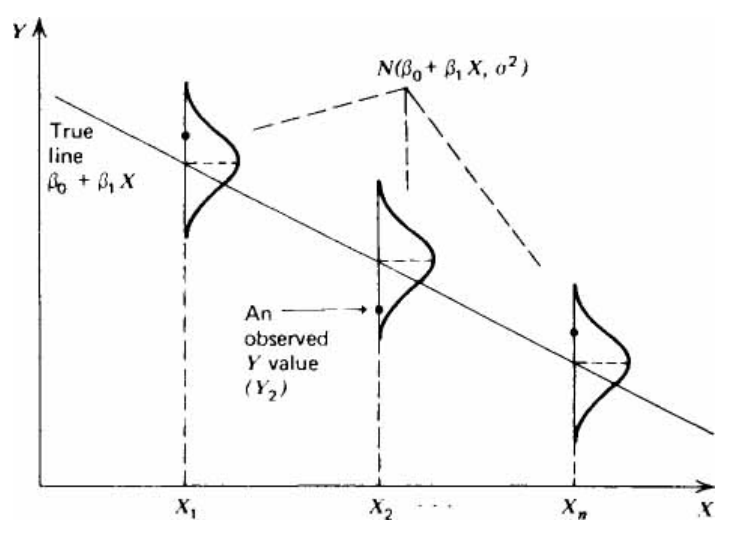


$$\vec{Y} = X\vec{\beta} +\vec{\epsilon}$$


Для каждого наблюдаемого значения Y ошибка берется из одного и того же стандартного распределения , сами габлюдаемые точки соотвественно распределены сог

$ \mathcal{N}(0,1)$ - стандартное нормальное распределение (функция randn)

Чтобы получить переменную, взятую из $\zeta \sim \mathcal{N}(\mu,\sigma^2)$ из переменной, взятой из стандартного распределения $ \eta \sim \mathcal{N}(0,1)$


$$\zeta \sim \mathcal{N}(\mu,\sigma^2) = \mu + \sigma^2 \mathcal{N}(0,1)$$


$\vec{Y} = \vec{\mu_Y} +\vec{\epsilon}$, 

где $\epsilon_i \sim \mathcal{N}(0,\sigma^2)$ - каждая координата вектора ошибки

$\vec{\mu_Y} =X\vec{\beta}$ - вектор средних значений

 $y_i\sim \mathcal{N}(X_{i1}\beta_1 + X_{i2}\beta_2 +...X_{iP}\beta_{P},\sigma^2) $ - то есть каждая координата вектора зависимой переменной  - это случайная величина, поученная из нормального распределения со своим средним значением, но дисперсия для всех одинаковая

Плотность вероятности для конкретной наблюдаемой точки будет:  


$$p(y_i;\mu_i,\sigma)= \frac {1}{\sqrt{2\pi\sigma^2}} e^{ \frac {-(y_i-\mu_i)^2}{2\sigma^2}}$$


Теперь зададимся вопросом, какова вероятность получить тот набор точек, который мы имеем?


$$P(\vec{Y}|\sigma^2) = [\frac {1}{\sqrt{2\pi\sigma^2}}]^N \prod_{i=1}^N e^{-\frac {(y_i-\mu_i)^2}{2\sigma^2}}= [\frac {1}{\sqrt{2\pi\sigma^2}}]^N e^{\frac {-\Sigma_i(y_i-\mu_i)^2}{2\sigma^2}}=[\frac {1}{\sqrt{2\pi\sigma^2}}]^N e^{-\frac {(\vec{Y} -X\vec{\beta})^T(\vec{Y} -X\vec{\beta})  }{2\sigma^2}}$$


Теперь, если рассмотреть данную вероятность как функцию параметров при измеренных значениях случайной величины, то она называется функция правдоподобия (likelihood):


$$\mathcal{L}(\vec{\beta}|\vec{Y})=[\frac {1}{\sqrt{2\pi\sigma^2}}]^N e^{-\frac {(\vec{Y} -X\vec{\beta})^T(\vec{Y} -X\vec{\beta})  }{2\sigma^2}}$$


Что мы отсюда видим:

- Уменьшение показателя экспоненты приводит к увеличению правдоподобия наших данных

- В показатели экспоннеты стоит $(\vec{Y} -X\vec{\beta})^T(\vec{Y} -X\vec{\beta}) =\vec{\epsilon}^T\vec{\epsilon}}$ - то есть максимизация правдоподобия эксвивалентна минимизации квадрата ошибки

- Отсюда можно интуитивно понять что нужно минимизировать, если ошибка для каждой точки получена из распределения с различной дисперсией


$$P(\vec{Y}|\sigma^2) \sim \prod_{i=1}^N e^{-\frac {(y_i-\mu_i)^2}{2\sigma_i^2}}=  e^{\Sigma_i\frac {-(y_i-\mu_i)^2}{2\sigma_i^2}}= e^{\frac{1}{2} \Sigma_i -(\frac{y_i}{\sigma_i}-\frac{\mu_i}{\sigma_i})^2}= e^{- {(\vec{Y'} -X'\vec{\beta})^T(\vec{Y'} -X'\vec{\beta})  }$$


$\vec{\epsilon} => W\vec{\epsilon}$, $W $ - диагональная матрица дисперсий ошибки, $X'$ - матрица предикторов, в которой каждая строка умножена на корень соотвествующего веса, $\vec{Y'}$ - вектор зависимой переменной в которой каждый элемент умножен на вес

Таки мобразом, чтобы учесть веса мы должны:


$$X'=>WX$$



$$Y'=>W\vec{Y}$$


Это дает формулу для линейной регрессии с весами:


$$\vec{b} = (X^TWX)^{-1}X^TWY$$


### Линейная регрессия с весами (weighted regression)

x = sort(rand(10,1));
y = 2 + 3*x + randn(size(x));


% добавляем веса последней точки путем повторения ее значения в выборке
nreps = 43
% просто повторим одну точку nreps раз
ax = get_next_ax();
plot(ax,[x;1],[y;9],'o');
hold(ax,"on");
plot(ax,[1],[9],'diamond',"MarkerFaceColor","r");
for n = [1,nreps]
    x2 = [x;ones(n,1)];
    y2 = [y;repmat(9,n,1)];
    % and solve
    M2 = [ones(size(x2)),x2];
    coef = M2\y2;
    yhat = M2*coef;
    plot(ax,x2,yhat,'-',"LineWidth",3);
end
hold(ax,"off")
xlim(ax,[0 1.2]);
ylim(ax,[1 10]);
legend(ax,["Данные","Последняя точка", "Все с одним весом", "Вес последней точки="+string(nreps)],"Location","best")
coef
grid(ax,"on")

% как можно сымитировать подобное поведение
x3 = [x;1];
y3 = [y;9];
weights = [ones(size(y));sqrt(nreps)];

M3 = [ones(size(x3)),x3];
% умножем каэдую строку матрицы предикторов на веса и кажд
coef = (diag(weights)*M3)\(weights.*y3)

% взвешенная регрессия делается функцией:
weights = [ones(size(y));nreps];
coef = lscov(M3,y3,weights)



### Локально-взвешенная линейная регрессия (local-weighted regression)

Основная идея локально взвешенной регрессии состоит в том, что мы задаем веса как некоторую функцию от независимых переменных таким образом, чтобы наибольший вес имели те точки, которые лежат в той области, которая представляет для нас наибольший интерес.

В следующем ниже примере мы будем пытаться описать квадратичную зависимость линейной, в качестве весов будет выступать функция:


$$f(x;\mu,\sigma)=\frac{1}{\sqrt{2\pi\sigma}}e^{\frac{(x-\mu)^2}{2\sigma^2}}$$


Она выглядит знакомо и удобна тем, что имеет максимум и два параметра, которыми регулируется ее ширина и положение этого максимума. Таким образом матрица весов будет:


$$W = diag(f(\vec{X}))$$


Таким образом, в окрестности координаты $x=\mu$ точки будут иметь наибольший вес.

Локально взвешенная регрессия сравнивается с классической линейной регрессией.

clearvars
N= 300;
x = randn(N,1);
x=sort(x);
y_measured = 2 + 0.4*x + x.^2 + 0.1*randn(N,1); % истинная модель
Ivect = ones(size(x));
X = [Ivect,x]; % матрица предикторов


% в качестве весовой функции выберем Гауссову функцию (она имеет два
% параметра, четкий максимум - удобно)
mu = -2.03;sig = 0.16;
weights_function = norm_distribution_function(mu,sig);
weights= weights_function(x);% вектор весов
coeff_unweighted = X\y_measured;
coef_weighted = (diag(weights)*X)\(weights.*y_measured);
ax = get_next_ax();
scatter(ax,x,y_measured);
hold(ax,"on")
plot(ax,x,X*coeff_unweighted,"LineWidth",2);
plot(ax,x,X*coef_weighted,"LineWidth",2);
yyaxis(ax,"right")
plot(x,weights*max(y_measured)/max(weights),"LineWidth",2);
hold(ax,"off")
grid(ax,"on")
legend(ax,["Data", "non-w", "local-w","W"],Location="best",BackgroundAlpha=0.5)

### Robust regression

    Робастная регрессия нужна в сех случаях, когда исходные данные имеют выбросы. Основная идея робастной регрессии состоит в том, чтобы сделать веса обратно пропорциональными (это может быть и некоторая функция, которая стремиться к нулю при увеличении аргумента) ошибкам регрессии, таким образом, стартуя с регрессия с равномерными весами, для которой выбросы будут иметь большой вклад в ошибку регрессии, можно постепенно прийти к регрессии с малыми весами выбросов.

    Данные будут представлять собой достаточно гладкую монотонную кривую, на которой будут отдельные случайные выбросы, выбросы будут иметь не гауссово распределение, поэтому их вклад в ошибку регрессии будет плохо описываться методом наименьших квадратов (см. принцип максимального правдоподобия). Весовая функция будет иметь форму :


$$f(\vec{\epsilon})= exp(-(\mu\vec{\epsilon}/max(\vec{\epsilon})^2)$$


$\mu$ - это параметр. В общем-то, функция может быть любой, главное, чтобы она спадала с ростом аргумента и стремилась в пределе к нулю, а при нулевой ошибке давала единицу, тот же гауссиан подходит.

% пример взят из [1]
clearvars
n = 20;
m = 3;% число выбросов
x = 2*rand(n,1) - 1;
x=sort(x);
y0 = exp(x); % создаются данные с простой монотонной зависимостью
%теперь к ним добавляются точки шума с негаусовой формой распределения  -
%выбросы
noise = randn(m,1)/2;
noise = sign(noise).*abs(noise).^4;
y = y0;
coeff_no_noise = polyfit(x,y0,4)
y(randi(n,[m 1]))= y(randi(n,[m 1])) + noise; % добавляем шумы к m случайным точкам


iterations = 3 % число итераций
% далее будем итерационно менять веса обратной пропорционально величине
% ошибки
% исходно все веса равны единице
mu = 4.93
weights = ones(n,1);

ax = get_next_ax();
plot(ax,x,y0,'ro',x,y,'b+',"MarkerSize",8)

% для решения задачи линейной регрессии будет исопльзоваться функция lscov
X = [x.^4,x.^3,x.^2,x,ones(size(x))]; 
% предикторы в матрице в обратном порядке, но это нормально
tb = table();
tb.("no noise")=coeff_no_noise(:);
hold(ax,"on");
for i = 1:iterations % производим несколько итераций
  poly = lscov(X,y,weights)';

  % ошибка регрессии
  resid = polyval(poly,x) - y; % для расчета исопльзуем поливал

  % find the maximum residual to scale the problem
  maxr = max(abs(resid));

  % расс
  weights = exp(-(mu*resid/maxr).^2);
  plot(x,polyval(poly,x),"LineWidth",2)
  tb.("iter "+ string(i))=poly(:);
end
hold(ax,"off")
iterstr = "итерация:" + string(1:iterations);
legend(ax,["Без выбросов", "С выбросами",iterstr ],"Location","best")
grid(ax,"on")
tb

Видно, что на третьей итерации мы получили очень близкие значения к данным без выбросов.

### Выводы

- Было рассмотрено обоснование метода наименьших квадратов с точки зрения принципа максимального правдоподобия

- Обсудили примеры линейной регрессии с весами (weighted regression)

- Локально-взвешенной регрессии (local-weighted regression) 

- Робастной регрессии (robust regression)

### Регуляризация Тихонова (ridge regression)

Столбцы матрицы предикторов - линейно зависимы (переобучение)

#### Линейная регрессия в различных платформах научного программирования (пример matlab, julia, python)

clearvars
data = load(fullfile(get_folder(),"DataSurfFit.mat"))
Y = data.y;
X1 = data.X(:,1);
X2 = data.X(:,2);
N = numel(X1);
scatter3(X1,X2,Y)
% матлаб statistical toolbox
mdl = fitlm(data.X,data.y)
mdl2 = fitlm([data.X,data.X.^2],data.y)

ЛИТЕРАТУРА

1. N.Draper, H.Smith . Applied regression analysis. Third edition. Wiley Series in Probability and Statistics. 

2.  Gilbert Strang - Introduction to Linear Algebra (2016, Wellesley-Cambridge Press)

3. John D'Errico (2025). Optimization Tips and Tricks (https://www.mathworks.com/matlabcentral/fileexchange/8553-optimization-tips-and-tricks), MATLAB Central File Exchange. Retrieved January 30, 2025.

#### Вывод формулы для коэффициентов линейной регрессии через статистические параметры

**Дополнение Шура (Schur complement) и инвертирование блочных матриц **

Если у нас есть блочная матрица вида:

$M=[\matrix{A \ & \ B \cr C \ & \ D}]$ ( то есть, матрица, у которой элементы - матрицы соотвествующего размера)

дополнение Шура  $Sh = D-CA^{-1}B$


$$[\matrix{A \ & \ B \cr C \ & \ D}]^{-1}=[\matrix{A^{-1}+ A^{-1}BSh^{-1}CA^{-1} & -A^{-1}BSh^{-1} \cr -Sh^{-1}CA^{-1}
& Sh^{-1} } ]$$


Формула справедлива когда матрицы $Sh$ и $A$- обратимы

[https://www.cis.upenn.edu/~jean/schur-comp.pdf](https://www.cis.upenn.edu/~jean/schur-comp.pdf)

#### Матричная форма линейной регрессии в статистической терминологии

Матрица модели: $X_{M}=[\vec{I}, X]$, теперь $X$ - матрица предикторов (размером *NxP*)

 $\vec{b}=[\matrix{b_0\cr \vec{b_1}}]=X_{M}^{\dagger}\vec{Y}=([\matrix{\vec{I}^T\cr X^T}][\vec{I}, X])^{-1}[\matrix{\vec{I}^T\cr X^T}]\vec{Y}=([\matrix{N \ &  \vec{I}^TX \ \cr X^T\vec{I} & X^TX}])^{-1}[\matrix{\vec{I}^T\cr X^T}]\vec{Y}$(*)

Вначале обратим внимание на кросс-диагональные 

элементы блочной матрицы:


$$\vec{I}^TX \frac{1}{N}=[\sum_{i=1}^NX_{i1},...,\sum_{i=1}^{N}X_{ij},...,\sum_{i=1}^{N}X_{i,P}]/N=[\overline{X}_1,...,\overline{X}_P]=\vec{\overline{X}}^T$$
 

То есть, $\vec{\overline{X}}$ - это вектор размером *Px1*, элементами которого являются средние значения столбцов матрицы $X$. С учетом этого, выражение (*) удобней переписать в виде:


$$[\matrix{b_0\cr \vec{b_1}}]=X_M^{\dagger}\vec{Y}=[X_M^{T}X_M]^{-1}X_M^T\vec{Y}=([\matrix{N \ &  N\vec{\overline{X}}^T \ \cr N\vec{\overline{X}} & X^TX}])^{-1}[\matrix{N\overline{Y}\cr X^T\vec{Y}}]$$


Вначале рассмотрим блочную матрицу $X_M^{T}X_M=[\matrix{N \ &  N\vec{\overline{X}}^T \ \cr N\vec{\overline{X}} & X^TX}]$.

Согласно формуле Шура, блочная матрица  $M=[\matrix{A &B\crС &D}]$ может быть инвертирована через  дополнение Шура: $Sh = D-СA^{-1}B$, $M^{-1}=[\matrix{A^{-1}+ A^{-1}BSh^{-1}CA^{-1} & -A^{-1}BSh^{-1} \cr -Sh^{-1}CA^{-1}
& Sh^{-1} } ]$

Для нашей конкретной матрицы:

$A^{-1}=\frac{1}{N}$ (просто скаляр), $B=N\vec{\overline{X}}^T$(вектор-строка),$C=N\vec{\overline{X}}$(вектор-столбец), $D=X^TX$(матрица PxP)


$$[X_M^TX_M]^{-1}=[\matrix{ N^{-1} +N^{-1}N\vec{\overline{X}}^TSh^{-1}N\vec{\overline{X}}N^{-1} \ & -N^{-1}N\vec{ \overline{X}}^TSh^{-1}\cr -Sh^{-1}N\vec{\overline{X}}N^{-1} & Sh^{-1}}]=[\matrix{ N^{-1} +\vec{\overline{X}}^TSh^{-1}\vec{\overline{X}} \ & \vec{ \overline{X}}^TSh^{-1}\cr -Sh^{-1}\vec{\overline{X}} & Sh^{-1}}]$$



$$[\matrix{b_0\cr \vec{b_1}}]=[X_M^{T}X_M]^{-1}X_M^T\vec{Y}=[\matrix{ N^{-1} +\vec{\overline{X}}^TSh^{-1}\vec{\overline{X}} \ & \vec{ \overline{X}}^TSh^{-1}\cr -Sh^{-1}\vec{\overline{X}} & Sh^{-1}}][\matrix{N\overline{Y}\cr X^T\vec{Y}}]$$


Посмотрим внимательно на выражение для вектора параметров $\vec{b_1}$:


$$\vec{b_1} = Sh^{-1}[ X^T\vec{Y}-N\vec{\overline{X}}\overline{Y}]$$


Оно  напоминает выражение для $b_1$ из формулы для прямой линии, только там $b_1$ - это был скаляр. Выражение в квадратных скобках имеет похожий смысл, как и выражение для Sxy, там $\vec{X}$ и $\vec{Y}$ были векторами, а их средние значения - скалярами, теперь $X$ - это матрица,  $\vec{\overline{X}}$ - вектор-столбец средних значений матрицы $X$ в каждом из столбцов. $X^T\vec{Y}$ - вектор, каждый элемент которого - скалярное произведение столбца матрицы $X$ на вектор $\vec{Y}$, вектор $\vec{\overline{X}}\overline{Y}$ - вектор, каждый элемент которого - произведение среднего значения столбца на $\overline{Y}$, то есть, среднее значения  зависимой переменной $\vec{Y}$. 

Теперь рассмотрим подробнее на дополнение Шура:

$Sh=X^TX- X^T\vec{I}\frac{1}{N}\vec{I}^TX$ - это матрица размером *PxP*.

С учетом определения вектор-столбца средних, его можно переписать в виде:


$$Sh = X^TX - N\vec{\overline{X}}\vec{\overline{X}}^T$$


Данное выражение практически полностью совпадает с выражением для $S_{XX}$, когда рассматрицалась одномерная задача. 

Обозначим $\overline{X}=\vec{\overline{X}}\vec{\overline{X}}^T$ матрицу размером *PxP*, элемент этой матрицы, стоящий на i-й строке j-го столбца равен произведению средних значений этих столбцов:


$$\overline{X}_{ij}=\overline{X_i} \ \overline{X_j}$$


% убедимся в том, что выражения действительно совпадают
clearvars
N=3
X=sym("X",[N 2],"real"); 
I = sym(ones(N,1))
Xmean = simplify(X'*I*I'*X)/N 
XmeanV = mean(X)'% функция mean автоматически считает среднее в каждой колонке
simplify(N*XmeanV*XmeanV' - Xmean)

Теперь, что такое $X^TX$, это матрица, в которой на i-й строке j-го столбца стоит скалярное произведение i-го столбца на j-й столбец матрицы X


$$[X^TX]_{ij}=\vec{X_i}^T\vec{X_j}$$


Таким образом, дополнение Шура - это матрица, в которой на i-й строке j-го столбца стоит:


$$[Sh]_{ij}=\vec{X_i}^T\vec{X_j} - N\overline{X_i} \ \overline{X_j}$$


% убедимся в том, что выражения действительно совпадают
clearvars
N=3
X=sym("X",[N 2],"real"); 
I = sym(ones(N,1))
Xmean = simplify(X'*I*I'*X)/N 
XmeanV = mean(X)'% функция mean автоматически считает среднее в каждой колонке
simplify(N*XmeanV*XmeanV' - Xmean)

Видно, что это матрица ковариации (умноженная на число измерений) матрицы, в которой столбцы  - это сэмлы случайной величины:


$$Sh=(N-1)Cov(X)$$


% убедимся в том, что выражения действительно совпадают
clearvars
N=3
X=sym("X",[N 2],"real"); 
XmeanV = mean(X)'% функция mean автоматически считает среднее в каждой колонке
Sh = simplify(X'*X - N*XmeanV*XmeanV')
Sigma= cov(X)*(N-1)
simplify(Sh-Sigma) % убеждаемся, что это матрица ковариации


Таким образом, окончательное выражение для вектора параметров линейной регрессии:


$$\vec{b_1} = [X^TX - N\vec{\overline{X}}\vec{\overline{X}}^T]^{-1}[ X^T\vec{Y}-N\vec{\overline{X}}\overline{Y}]$$


function M = join_matrix(UL,UR,DL,DR,w,val)
% функция скледивает четыре матрицы в одну, вставляя между ними нул, так,
% чтобы была рамка на картинке
    arguments
        UL
        UR
        DL
        DR
        w = 10
        val = 0;
    end
    r1 = size(UL,1);r2 = size(DL,1);
    c1 = size(DL,2);c2 = size(DR,2);
    M = ones(r1+r2+w,c1+c2+w)*val;
    M(1:r1,1:c1) = UL;
    M(1:r1,(c1+w+1):end)=UR;
    M((r1+w+1):end,1:c1) = DL;
    M((r1+w+1):end,(c1+w+1):end) = DR;   
end
function data = read_bottle_dataset(vars)
        data = struct();
        info = h5info(filename)
        data = h5read("E:\projects\datasets\bases\bottle\bottle.h5",ds) 
        % Open HDF5 file
        % fileID = H5F.open("E:\projects\datasets\bases\bottle\bottle.h5");
        % 
        % data.Datasets(1).Name = "BtlNum";
        % dsID1 = H5D.open(fileID, "/BtlNum");
        % data.Datasets(1).Value = H5D.read(dsID1);
        % 
        % data.Datasets(2).Name = "Depthm";
        % dsID2 = H5D.open(fileID, "/Depthm");
        % data.Datasets(2).Value = H5D.read(dsID2);
end
function rus_name = rus(type)
    possible_types =  ["stand" "legA" "trig" "legP" "custom"];
    possible_rus_names = ["Стандартный базис" "Присоединенные полиномы Лежандра" "Тригонометрический базис" "Полиномы лежандра" "Кастомный"];
    flag = possible_types==type;
    if any(flag)
        rus_name = possible_rus_names(flag);
    else
        rus_name = type;
    end

end
function val = convert_rating_to_number(rating)
    %rating = string(rating);
    switch rating(1)
        case "A"
            val = 7+count(rating,"A");
        case "B"
            val = 8-count(rating,"B");
        case "C"
            val = 4-count(rating,"C");
    end
end
function f = norm_distribution_function(mu,sig)
% возвращает анонимную функцию для нормального распределения
    f =@(x) exp(-(x-mu).^2./(2*sig^2))./(sig*sqrt(2*pi));
end
function [V,s] = vandermatrix(t,P,type,polyprod_function)
arguments
    t double
    P (1,1) double {mustBeInteger,mustBePositive} = 2
    type (1,1) string {mustBeMember(type,["stand" "legA" "trig" "legP" "custom"])} = "stand"
    polyprod_function =[]
end
% создаем матрицу Вандермонда
% type - тип полинома (стандартный базис, полиномы лежандра,
% тригонометрические полиномы)
    t = t(:);
    N = numel(t);
    V = zeros(N,P);
    if ~(type=="custom")
        [Pfun,s] = producing_function(type,t); % возвращаем производящую функцию для колонки матрицы вандермонда
    else
        assert(~isempty(polyprod_function)||~isa(polyprod_function,"function_handle"),"Если выбрана кастомная производящая функция, то нужно ее предоставить")
        s = normalize(t);
        Pfun = @(i)polyprod_function(i,s.x);
    end
    for jj = P:-1:1
        V(:,jj) = Pfun(jj);
    end
end
function dist= make_dist(type,options)
% возращает генератор N случайных чисел, распределенных в соответствии 
% с двух параметрическими распределениями: нормальным, дельта-равномерным,
% Вейбулла и Хи-квадрат
    arguments
        type (1,1) string {mustBeMember(type,["Normal" "Uniform" "Weibull" "Chi2"])}
        options.mu (1,1) =0
        options.sig (1,1)=0
    end
    mu=options.mu;
    sig2=options.sig^2;
    switch type
        case "Normal"
            dist = @(N) mu + sig2*randn([N 1]);
        case "Uniform"
            dist  = @(N)   sqrt(sig2)*(rand([N 1])  -0.5)+ mu;
        case "Weibull"
            dist  = @(N) wblrnd(mu,sqrt(sig2),N,1);
        case "Chi2"
            dist = @(N) (mu + sig2*randn([N 1]).^2);
    end

end
function norm_struct = normalize2(t)
% функция возвращает стурктуру, в которой хранятся данные для нормировки
    if ~issorted(t)
        t = sort(t,"ascend"); 
    end
    tmin = t(1);
    tmax = t(end);
    x = 2.0*((t - tmin) / (tmax - tmin))- 1; 
    norm_struct = struct("tmin",tmin,"tmax",tmax,"x",x); %t,(max(t) - min(t))    
end
function t = denormalize2(s)
    t = 0.5*(s.x + 1.0)*(s.tmax - s.tmin) + s.tmin;
end
function Pn = leg_polyA(i,t) % производящая функция для присоединенных полиномов Лежандра 
    persistent P 
    persistent tleg
    leg_type = 'norm';
    if isempty(tleg)||isempty(P)||(~isequal(t,tleg))
        P = transpose(legendre(i-1,t,leg_type)); % встроенная функция по сути возвращает уже матрицу Вандермонда
        tleg = t;
    end
    if i<=size(P,2)
        Pn = P(:,i);
        return
    end
    P = transpose(legendre(i,t,leg_type));
    tleg = t;
    Pn = P(:,end);
end
function Pn = trig_poly(i,t) % производящая функция для тригонометрических полиномов
    if i==1
        Pn  = ones(size(t));
        return
    end
    if mod(i,2)==0
        Pn = cos(i*t*pi);
    else
        Pn = sin(i*t*pi);
    end
end
function [P,s] = producing_function(type,t)
% функция возвращает производящую функцию для полинома
    s = normalize2(t);
    switch type
        case "stand" % стандартный базис полинома
          P = @(i) s.x.^(i-1);  
        case "legA" % присоединенные полиномы Лежандра
          P = @(i) leg_polyA(i,s.x); 
        case "legP" % полиномы Лежандра
          P = @(i) legendreP(i-1,s.x) ; % стандартная фукнция для полиномов лежандра
        case "trig" % тригонометрический базис
          P = @(i) trig_poly(i,s.x);  

    end
    
end
function [new_ax,fig_handle] = get_next_ax(index, axes_name_value_pairs)
% функция, которая возвращает новые оси на новой фигуре (нужна чтобы
% кратинки в ливскрипте нормально строились)
    arguments
        index = []
        axes_name_value_pairs cell = {}
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);        
        clf(fig_handle);
        new_ax = axes(fig_handle,axes_name_value_pairs{:});
        %disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle,axes_name_value_pairs{:});    
    end
end
function ax = get_named_ax(title_string)
    ax = get_next_ax();
    title(title_string);
end
function ax = draw_vector(ax,ttl,names,type,varargin)
% функция строит двух- и трех-мерные вектора, а также рассеянные данные из
% матрицы
% ax - оси (если пустые, то создаются новые)
% ttl - заголовок картинки
% names - имена векторов
% type:
%       "vector" - аргументы, которые передаются после интерпретируются
%                   как отдельные вектора
%       "point"  - в этом случае передается матрица в качестве аргумента и
%       столбцы матрицы строятся при помощи функций scatter и scatter3 d
%       в зависимости от размерности массива
    arguments
        ax =[]
        ttl string =strings(0,1)
        names string =strings(0,1)
        type string {mustBeMember(type,["vector" "point"])}="vector"
    end
    arguments (Repeating)
        varargin double
    end
    was_empty = isempty(ax); % это признак того, что все строится на новых осях
    if was_empty
        ax = get_next_ax();
    else
        hold(ax,"on");
        % if ~isempty(ax.Legend)
        %     leg_before = ax.Legend.String;
        % else
        %     leg_before = strings(0,1);
        % end
    end
    
    if strcmp(type,"vector")
        is_3D = numel(varargin{1})==3;
            if is_3D
                [x,y,z]  = make_xy(varargin{1});
                plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y,z] = make_xy(varargin{iii});
                        plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off                
            else
                [x,y]  = make_xy(varargin{1});
                plot(ax,x,y,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y]  = make_xy(varargin{iii});
                        plot(ax,x,y,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off
            end
            if isempty(names)||(numel(names)~=numel(varargin))
                legend(ax,string(1:numel(varargin)));
                
            else
                % if ~was_empty
                %      names= [names(:);leg_before(:)];
                % end
                legend(ax,names);
            end
            xlim(ax,[-1 1]);
            ylim(ax,[-1 1]);
            if ~isempty(ttl)
                title(ax,ttl);
            end
    else
        %data_number = numel(varargin); % число массивов данных
        is_3D = numel(varargin)==3;
        data = varargin{1};
        if size(data,2)>1
            data = transpose(data);
            is_transpose = true;
        else
            is_transpose = false;
        end
        if ~is_transpose
            for iii = 2:numel(varargin)
                data = [data,varargin{iii}];
            end
        else
            for iii = 2:numel(varargin)
                data = [data,transpose(varargin{iii})];
            end            
        end

        if is_3D
            scatter3(ax,data(:,1),data(:,2),data(:,3));
        else
            scatter(ax,data(:,1),data(:,2));
        end

    end
    if ~was_empty
            hold(ax,"off");
    end
end
function [x,y,z]  = make_xy(col)
% добавляет к координатам вектора нули так, чтобы при помощи функции plot
% строилась линия
    switch numel(col)
        case 1
            x = [col(1)];
            y = 0;
            z = 0;
        case 2
            x = [0 col(1)];
            y = [0 col(2)];
            z = zeros(1,2);
        case 3
            x = [0 col(1)];
            y = [0 col(2)];
            z = [0 col(3)];
    end
end
function folder = get_folder()
% текущая папка
folder = fileparts(matlab.desktop.editor.getActiveFilename);
end
function [sampling_volume,tests_number,beta_mat] = sampling_surf_plot(beta,Nmax,Mmax,delta)
        % N
        P = numel(beta);
        sampling_volume = 2:Nmax;
        tests_number = 2:Mmax;
        beta_mat = zeros([Nmax-1,Mmax-1,P]);
        for N=sampling_volume % первый индекс - объем выборки
            x = transpose(linspace(-1,1,N));% столбец координат
            X = vandermatrix(x,P); % матрица вандермонда
            Yo = X*beta;% истинное значение 
            for ii = tests_number% второй индекс - номер теста
                Y = Yo + delta*randn(N,1);
                b_values = X\Y;
                beta_mat(N-1,ii-1,:) = b_values;
            end
        end
end